# Introduccion

Esta practica es una version traducida y adaptada del curso "Signal Processing Onramp" a la asignatura de Señales y Sistemas. La introduccion al curso puede verse [aqui](https://youtu.be/lqI7eOGsOV4). Las aplicaciones de analisis de señal tipicamente incluyen tres etapas, una de acondicionamiento y adaptacion de señales, denominada genericamente etapa de preprocesado. Una segunda etapa de analisis de las caracteristicas relevantes de la señal, y finalmente una tercera etapa de extraccion de algun tipo de informacion relevante, a traves del calculo de diferentes metricas o medidas sobre la señal. En esta practica se pretende mostrar el proceso completo en una aplicacion real, desde la adquisicion de las señales hasta la extraccion de informacion a partir de sus caracteristicas temporales y espectrales. La aplicacion consiste en el analisis comparativo de tres señales sismicas procedentes de tres estaciones de medida situadas en Alaska: HARP, PAX y WANC. Las señales registraron un terremoto de magnitud M9 localizado en Sumatra (Indonesia) el 12/26/2004, que a su vez dio lugar a un gigantesco tsunami, provocando grandes destrozos materiales y personales. Las estaciones de medida en Alaska estan situadas en el otro extremo de la tierra, a unos 11000km, y las tres estaciones estan muy proximas entre ellas, entorno a unos 100km. Un terremoto desplaza las rocas de la corteza terrestre, generando vibraciones que dan lugar a ondas sismicas que se propagan por la superficie de la tierra.

# Esquema general del problema

En esta seccion veremos resumidamente el flujo de trabajo para el analisis de señales en un problema real. En primer lugar abordamos la generacion de señales simuladas, que suelen ser muy utiles para implementar modelos teoricos y poner a punto los algoritmos. Despues importaremos al espacio de trabajo las señales reales, que en este caso son medidas en las estaciones sismicas, las cuales es necesario adaptar y acondicionar mediante la etapa de preprocesamiento. Esta etapa abarca procedimientos como la normalizacion, alineamiento, remuestreo, etc. Posteriormente, las señales se analizan en el dominio del tiempo y de la frecuencia, este ultimo obtenido mediante la transforamda de fourier. Segun las caracteristicas del espectro, puede ser necesario realizar diferentes tipos de filtrado para visualizar mejor las caracteristicas de la señal en diferentes bandas espectrales. Segun se van conociendo mas detalles sobre las señales y su fenomenologia es posible volver al inicio y modificar el preprocesado para adaptar mejor la señal al procedimiento deseado, en una especie de bucle. Finalmente, puede ser necesario calcuar ciertos parametros sobre la señal, como en este caso puede ser la localizacion de los instantes en los que se inicia un terremoto, o bien se puede pensar en implementar el algoritmo en hardware/software para su despliegue en forma de herramienta para el analisis de otros terremotos. En la siguiente figura se ilustra el procedimiento esquematico:

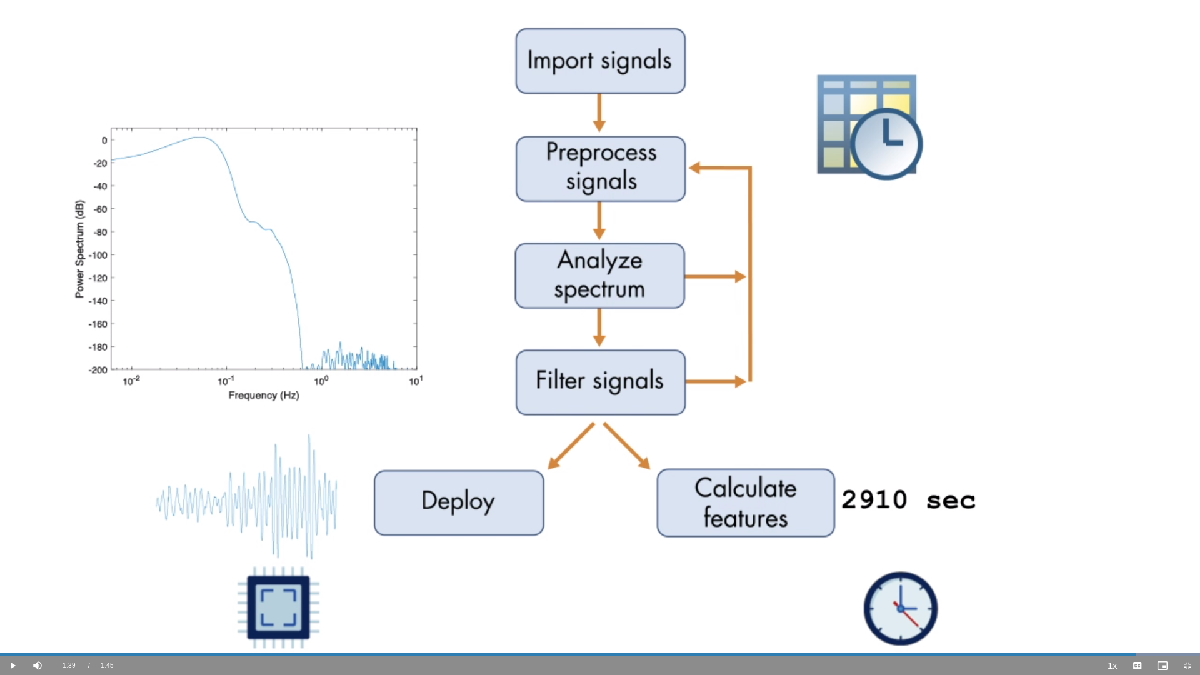

## Generación de señales 

Cuando se trabaja con datos realistas, como en este caso las señales sísmicas, probablemente no se sabe el resultado "esperable" en cada paso del flujo de trabajo. Si se utiliza una señal sintética, se puede comprobar si el algoritmo funciona según lo esperado. Por ejemplo, ¿cómo se puede saber si se ha calculado correctamente la transformada de Fourier de una señal sísmica? Probando el algoritmo con una onda sinusoidal simulada cuyo contenido espectral es conocido!. Un ejemplo de señal sinusiodal, junto con su espectro se muestra en la siguiente grafica:

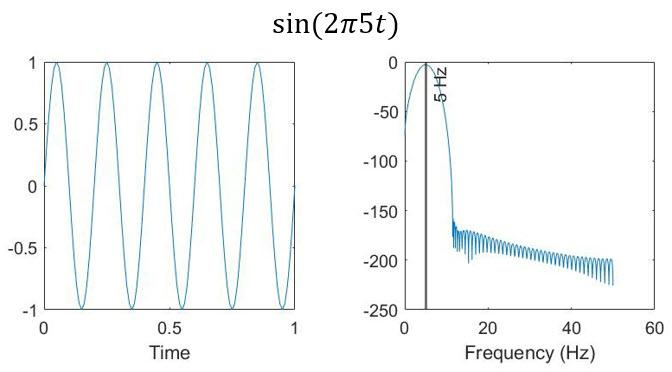

En primer lugar hay que definir un vector donde se definen los valores temporales correspondientes a cada muestra de la señal que vamos a generar. Podemos elegir las muestras de tiempo especificando:

- Frecuencia de muestreo: `fs`

- Comienzo

- Final

Se pueden crear las muestas temporales comenzando en "`a`" y terminando en "`b`" utilizando el operador "`:`", del siguiente modo: 

`t = a``:``1``/``fs``:``b. `

**ACTIVIDAD**

Especifique en la siguiente celda una frecuencia de muestreo de 100Hz en la variable `fs `y defina una señal que se llame `t` y que contenga las muestras temporales desde `0s` a `1s`, con las muestras correspondientes al periodo de muestreo:` Ts = 1/fs`.

%Frecuencia de muestreo
fs = 100;
t = 0: 1/fs : 1; %Vector de tiempos

Una forma de generar una función sinusiodal es con la función "`sin", por ejemplo:` 

`s` `=` `sin``(``2``*``pi``*``f``*``t``), `

donde `f` es la frecuencia y `t` es la variable asociada a las muestas temporales. 

**ACTIVIDAD**

Cree una señal sinusoidal denominada `sig`, con las muestras temporales asignadas en `t y con una `frecuencia de 5Hz. Además, genere una gráfica que permita representar `sig` respecto de `t`. Es una buena costumbre poner las etiquetas en cada eje, junto con las unidades, si las hay. Si no las hay se suelen poner "unidades arbitrarias".

%Señal: valores de tiempo evaluadas en sinusoidal de 5 Hz 
f = 5;
sig = sin(2*pi*f*t) 

sig =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


Es muy común añadir ruido a una señal simulada, para conseguir un efecto realista y asegurar que los algoritmos sean robustos frente al efecto del ruido, ya que es un fenómeno que casi siempre está presente. Para añadir ruido, se puede crear un vector de números aleatorios con el mismo tamaño que la señal original, por ejemplo con la función: `randn``(``size``(``s``)). `

**ACTIVIDAD**

Genere un vector de números aleatorios con una función de distribución normal, el vector se llama `noise` y es del mismo tamaño que `sig`.  Multiplique el vector por `0.1` para que tenga un efecto razonablemente visible sobre la señal. A continuación, añade el vector de ruido a la señal, llamándo al resultado `sigNoisy`. Finalmente cree una gráfica que represente `sigNoisy` respecto de `t`.

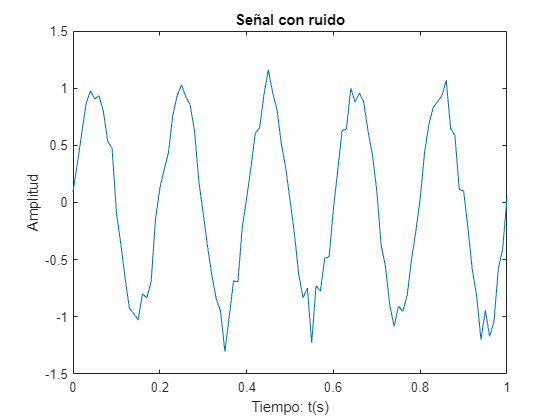

noise = 0.1*randn(size(sig)); %0.1 para que no sea tanto ruido
%Añadimos ruido con suma
sigNoisy = sig + noise;
%Representación
plot(t,sigNoisy);
xlabel("Tiempo: t(s)");
ylabel("Amplitud");
title("Señal con ruido");

La Toolbox de Procesado de Señal contiene funciones para generar diferentes formas de onda o señales básicas, como puede ser un tren de rectángulos o una señal con dientes de sierra. La sintaxis es similar a la de la función `sin,` por ejemplo un tren de rectángulos sería: 

`s` `=` `square``(``2``*``pi``*``f``*``t``)`, 

`donde f` es la frecuencia y `t` es el vector que contiene los valores temporales de las muestras.

**ACTIVIDAD**

Cree un tren de rectángulos denominado `sq` en las muestras temporales definidas en `t` y con una frecuencia de `5`Hz. Finalmente represente en una gráfica la señal respecto del tiempo:

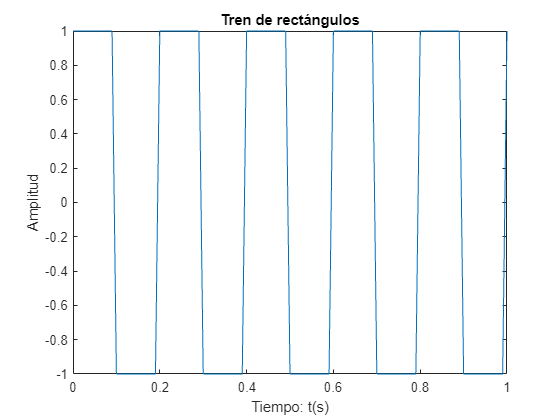

%Tren de rectángulos (con misma frecuencia)
sq = square(2*pi*f*t);
%Representación
plot(t,sq);
xlabel("Tiempo: t(s)");
ylabel("Amplitud");
title("Tren de rectángulos");

**Actividad**

Añada el ruido `noise` a la onda cuadrada y represente el resultado.

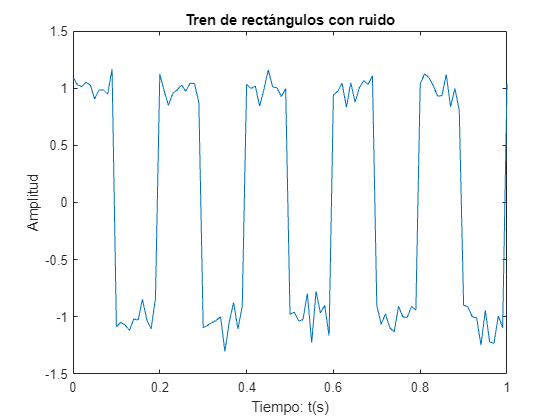

%Añadimos ruido
sqNoise = sq + noise;
%Representación
plot(t,sqNoise);
xlabel("Tiempo: t(s)");
ylabel("Amplitud");
title("Tren de rectángulos con ruido");

## Importacion de señales

Los registros sismicos se guardan en un "dataset" de cuatro archivos. El archivo `seismicstation_ts.csv` contiene el periodo de muestreo de los sismografos de cada estacion de medida y los tres archivos restantes contienen las lecturas de los sismografos: 

- `harp.csv` 

- `pax.csv` 

- `wanc.csv`. 

La funcion `readmatrix` importa un array numerico de un archivo, por ejemplo. 

`M` `=` `readmatrix``(``"mynum.txt"``)`

`M` `=` `2``x4`

     `6`     `8`     `3`     `1`

     `5`     `4`     `7`     `3`

**ACTIVIDAD**

Importe los perioddos de muestreo almacenados en `"seismicstation_ts.csv"` en una variable llamada `Ts`. Omita el "`;`" del final del comando para ver el resultado.

%Importamos periodos de muestreo (como array) almacenados en archivo
Ts = readmatrix("seismicstation_ts.csv");

La variable `Ts` contiene el periodo de muestreo de los tres sismografos localizados en las estaciones `HARP`, `PAX`, y `WANC, respectivamente`. Como se puede ver, las señales HARP y PAX tienen el mismo periodo de muestreo, que es el doble de la señal WANC. Para comenzar, vamos a importar la señal sismica de la estacion `HARP`, pero antes de ello almacenamos el periodo de muestreo en una variable.

**ACTIVIDAD**

Guarde el primer elemento de `Ts` en la variable llamada `harpTs`.

%El primer elemento del array es el del sensor Harp
harpTs = Ts(1)

harpTs = 0.0200

### Tabla temporal de datos

Una estructura tabular de datos (tambien llamada tabla temporal, o `timetable`) es una tabla que contiene señales almacenadas por columnas, donde cada fila corresponde las muestras de las diferentes señales asociadas a un determinado instante temporal. Es parecido a una hoja excel en Microsoft o un `framework` en Pandas (python). Se pueden importar los datos de un archivo en una estructura de tabla temporal con la funcion `readtimetable`, para ello es necesario facilitar la frecuencia de muestreo` "SampleRate"` como opcion, para porder asociar el instante temporal en el que ocurre cada muestra.

`mytbl` `=` `readtimetable``(``"fn.txt"``,``"SampleRate"``,``Fs``),`

donde la frecuencia de muestreo es la inversa del periodo de muestreo y suele expresarse en Hercios.

**ACTIVIDAD**

Importe la señal guardada en el archivo `"harp.csv"` en una tabla temporal llamada `harp`, especificando la frecuencia de muestreo. Omita el "`;`" final para mostrar por pantalla el resultado.

%Tabla temporal de la señal medida por Harp
%Frecuencia de muestreo
harpFs = 1/harpTs;
harp = readtimetable("harp.csv","SampleRate",harpFs)

harp = 240000×1 timetable
      Time      Signal
    ________    ______

    0 sec       -3094 
    0.02 sec    -3108 
    0.04 sec    -3126 
    0.06 sec    -3149 
    0.08 sec    -3172 
    0.1 sec     -3204 
    0.12 sec    -3242 
    0.14 sec    -3282 
    0.16 sec    -3322 
    0.18 sec    -3361 
    0.2 sec     -3402 
    0.22 sec    -3438 
    0.24 sec    -3473 
    0.26 sec    -3503 
    0.28 sec    -3531 
    0.3 sec     -3555 


Como se puede ver, `harp` es una tabla con una variable denominada `Signal`, que es el nombre que aparece como cabecera en la primera linea del archivo con extension `csv`. Para representar graficamente las señales de una tabla, se puede acceder a las variables a traves de la notacion basada en el nombre de la tabla, seguida de un punto y el nombre de la variable: `tdata.VariableName`

**ACTIVIDAD**

Represente una grafica de la señal `harp.Signal` respecto de `harp.Time`.

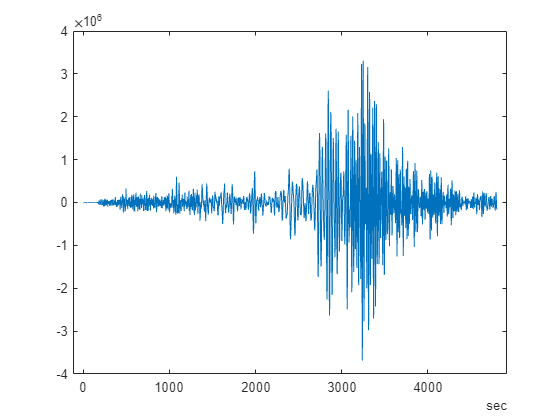

%harp es un variable que es una tabla temporalç
%Para acceder al tiempo y valor, son campos de la estrcutura harp
plot(harp.Time,harp.Signal)

**ACTIVIDAD**

Se pueden crear tablas utilizando el periodo de muestreo en lugar de la frecuencia de muestreo, para ello es necesario especificar la opcion adecuada junto con el periodo de muestreo con sus unidades. Se pueden usar funciones como `milliseconds`, `seconds`, y `minutes` para dar unidades a los arrays utilizados como argumentos. Importe la tabla temporal `harp` con la opcion `"TimeStep"` de la funcion `readtimetable. `Configure  `"TimeStep" `con la variable` harpTs `expresada en segundos mediante la funcion `seconds``(``harpTs``)`.

%Creamos la misma tabla temporal, pero usando Ts, lo indicamos como opción
harp = readtimetable("harp.csv","TimeStep",seconds(harpTs))

harp = 240000×1 timetable
      Time      Signal
    ________    ______

    0 sec       -3094 
    0.02 sec    -3108 
    0.04 sec    -3126 
    0.06 sec    -3149 
    0.08 sec    -3172 
    0.1 sec     -3204 
    0.12 sec    -3242 
    0.14 sec    -3282 
    0.16 sec    -3322 
    0.18 sec    -3361 
    0.2 sec     -3402 
    0.22 sec    -3438 
    0.24 sec    -3473 
    0.26 sec    -3503 
    0.28 sec    -3531 
    0.3 sec     -3555 


## Preprocesado

El registro y la adquisicion de señales suele ser un proceso complicado, con sensores imperfectos, y en ocasiones desconocidos, los cuales generan señales distorsionadas, con errores, y segun el sensor, con diferentes formatos. Las amplitudes que genera cada sensor dependen de su ganancia y escala, y en ocasiones la amplitud no suele ser un factor relevante como tal, ya que se analiza de forma relativa. Una tarea tipica de preprocesado suele ser la normalizacion de las amplitudes de las señales, para que todas tengan una escala comun, de modo que las comparativas entre ellas se visualicen de un modo mas comodo. Por otro lado, tipicamente las señales se registran y almacenan con un muestreo uniforme, es decir, con un periodo de muestreo fijo. Sin embargo, diferentes sensores pueden tener diferentes periodos de muestreo, como se puede ver en la siguiente grafica. 

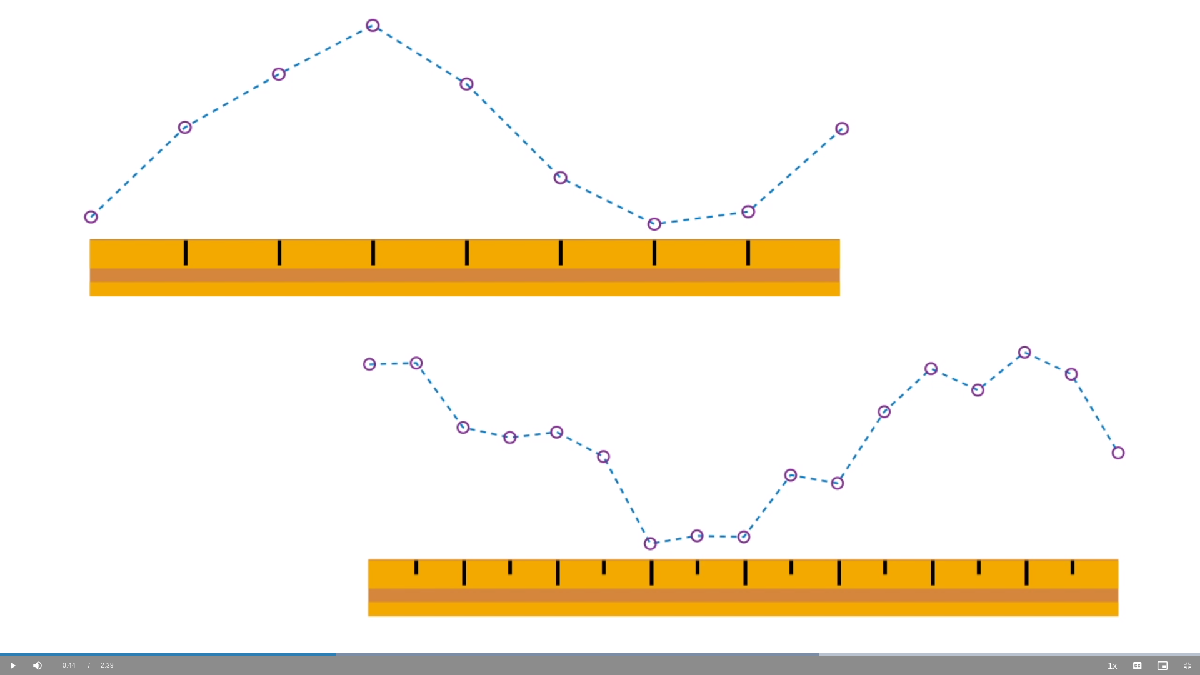

Cada señal tiene un vector de tiempos que viene determinado por el instante inicial, el final y el periodo de muestreo. En primer lugar, antes de establecer comparativas entre señales, es necesario definir un periodo comun mediante interpolacion o diezmado, de modo que todas las señales tengan el mismo periodo de muestreo. Ademas de ello, tenemos que definir un mismo vector de tiempos para todas ellas, de modo que quede determinado el instante en el que se produce cada muestra. Es decir, las señales solo se pueden comparar en las regiones en las que el dominio temporal coincide, en los mismos instantes de tiempo. Los vectores de tiempo no suelen tener informacion absoluta del tiempo, mas bien es una ordenacion temporal de forma relativa. Para unificar todos los vectores de tiempo, en ocasiones es necesario alinear temporalmente las señales (desplazandolas), de modo que coincidan todos los vectores de tiempo. Una vez alineadas, nos quedamos con los instantes de tiempo donde todas las señales estan definidas simultaneamente, como se puede ver en la siguiente grafica:

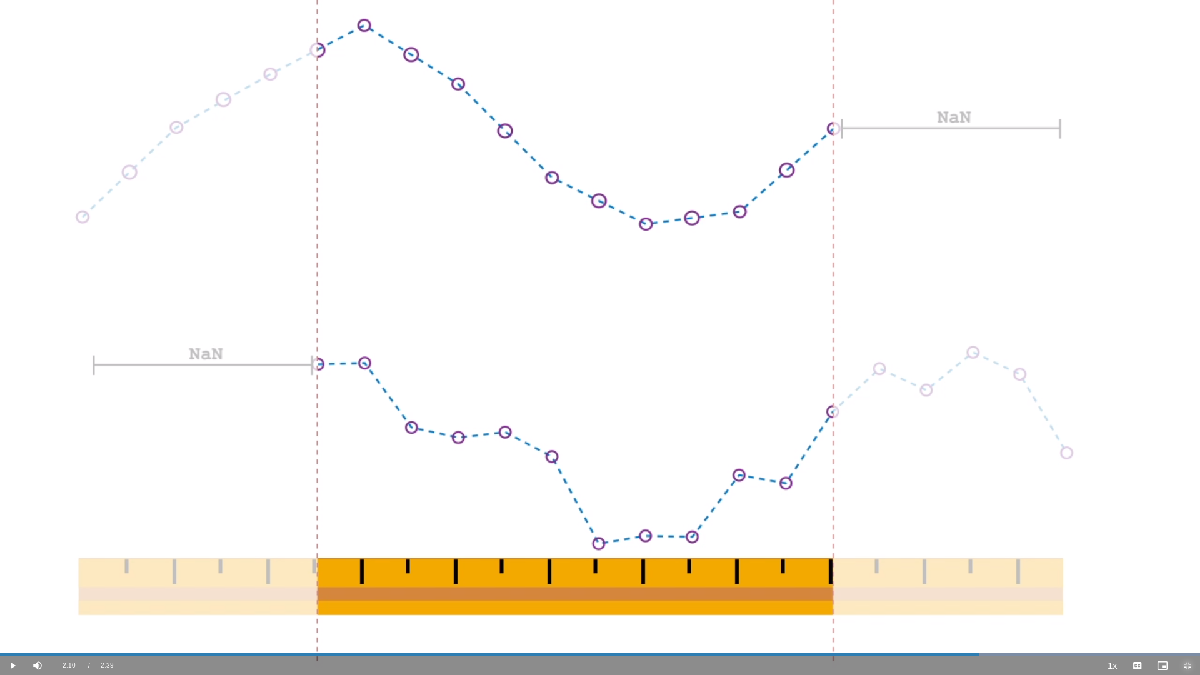

Teniendo en cuenta estas consideraciones, antes de analizar las señales suele ser interesante realizar todas estas labores de preprocesado. Los procedimientos suelen incluir:

- Normalizacion

- Remuestreo

- Alineacion

En primer lugar vamos a importar la señal `harp` y la representamos graficamente:

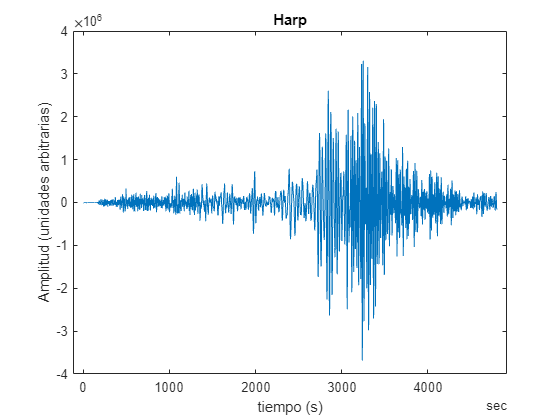

Ts = readmatrix("seismicstation_ts.csv");
harp = readtimetable("harp.csv","SampleRate",1/Ts(1));
plot(harp.Time,harp.Signal)
title('Harp')
xlabel('tiempo (s)')
ylabel('Amplitud (unidades arbitrarias)')

En el caso de las señales sismicas, es interesante extraer los datos correspondinetes al momento en el que se produce el terremoto. En el caso en el que se conozca el principio y el final de un evento se puede definir el intervalo de tiempo de interes (ROI, region of interest), que sera el que se analice. Para definir los limites del intervalo es necesario especificar las unidades de tiempo de cada valor, para ello se puede utilizar, por ejemplo, la funcion `seconds: `

`nsec` `=` `seconds``(``n``)`

**ACTIVIDAD**

Cree las variables que definnen el principio, `tstart`, y el final, `tend`, que continenen los valores 2000 y 4000 segundos, respectivamente. 

%Vamos a establecer intervalo de tiempo en el que se miden los datos
%Extremos
tstart= seconds(2000);
tend = seconds(4000);

El rango temporal de una tabla temporal de señales se puede definir con la funcion `timerange`: 

`lim` `=` `timerange``(``t1``,``t2``)`

**ACTIVIDAD**

Utilice la funcion `timerange` para especificar el rango de valores situados entre `tstart` y `tend en `segundos. El rango de valores se debe almacenar en una variable denominada `timeLimits`.

%Rango de valores, pasamos variables en segundos
timeLimits = timerange(tstart,tend);

En una tabla temporal de señales, cada fila se asocia a un instante de tiempo, para seleccionar todas las señales en un rango temporal se puede usar el operador "`:`":

`tbl` `=` `tbl``(``lim``,:``)`

**ACTIVIDAD**

Extraiga el rango temporal de la señal HARP correspondiente al intervalo definido por `timeLimits`. Reasigne la salida con el mismo nombre de la tabla, `harp`.

%Rango temporal de harp
%Limitamos filas (tiempos) con lo que queramos (de 2000 a 4000)
harp = harp(timeLimits,:)

harp = 100000×1 timetable
       Time         Signal   
    __________    ___________

    2000 sec      -2.5281e+05
    2000 sec      -2.5464e+05
    2000 sec      -2.5644e+05
    2000.1 sec     -2.582e+05
    2000.1 sec    -2.5997e+05
    2000.1 sec    -2.6171e+05
    2000.1 sec    -2.6343e+05
    2000.1 sec    -2.6514e+05
    2000.2 sec    -2.6685e+05
    2000.2 sec    -2.6858e+05
    2000.2 sec     -2.703e+05
    2000.2 sec    -2.7203e+05
    2000.2 sec    -2.7374e+05
    2000.3 sec    -2.7545e+05
    2000.3 sec    -2.7719e+05
    2000.3 sec    -2.7895e+05


%Contiene tambíen los extremos

Observese como la primera fila de `harp` comienza ahora en 2000 segundos.

**ACTIVIDAD**

Represente la señal preprocesada correspondiente al segmento de interes de la señal HARP.

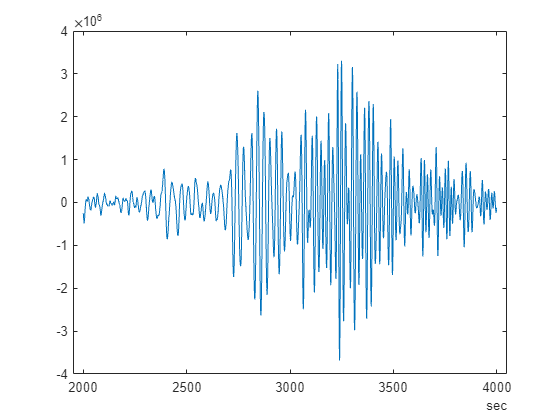

plot(harp.Time,harp.Signal)

Como ves, la señal va desde los 2000 a 4000 segundos. ¿Las muestras correspondientes a 2000 y 4000 segundos estan incluidas en el rango? Chequee la documentacion de [`timerange`](https://www.mathworks.com/help/matlab/ref/timerange.html#bvdk6vh-intervalType) para encontrar el valor por defecto de la propiedad que lo define, denominada `intervalType`. 

## Visualizacion del espectro de potencia

El espectro de potencia o densidad espectral de potencia es la proporcion de potencia que esta contenida en cada frecuencia que compone la señal. La integración de la densidad espectral de potencia da lugar a la potencia total de la señal, tal y como se obtendria en el dominio del tiempo, segun el teorema de Parseval. Formalmente, la densidad espectral de potencia es el modulo al cuadrado de la transformada de Fourier:


$$S_x(f) = \left|X(f)\right|^2$$


La densidad espectral de potencia se suele expresar en W/Hz y descarta la informacion de la fase de la transformada de Fourier. En ocasiones, con el objetivo de visualizar un rango amplio en la magnitud de la densidad espectral de potencia, se suele expresar en decibelios mediante la expresion $10\log_{10}{S_x}$. Para obtener mas informacion sobre la densidad espectral de potencia puede consultar en [Wikipedia](https://en.wikipedia.org/wiki/Spectral_density). La densidad espectral de potencia de una señal en Matlab se puede calcular mediante la funcion `pspectrum: `

`pspectrum``(``mysig``).`

Antes de comenzar, al igual que antes, importamos la señal y la visualizamos:

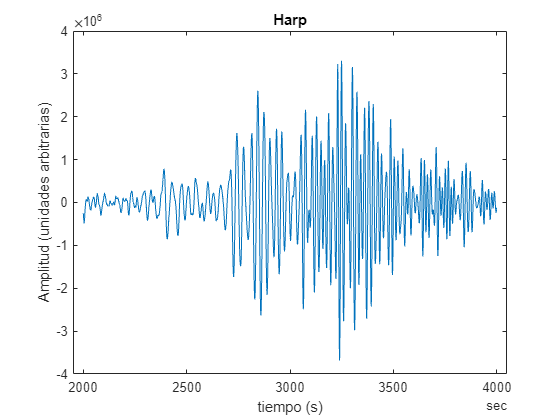

Ts = readmatrix("seismicstation_ts.csv");
harp = readtimetable("harp.csv","SampleRate",1/Ts(1));
timeLimits = timerange(seconds(2000),seconds(4000));
harp = harp(timeLimits,:);
plot(harp.Time,harp.Signal)
title('Harp')
xlabel('tiempo (s)')
ylabel('Amplitud (unidades arbitrarias)')

**ACTIVIDAD**

Si no se usan argumentos de salida, la funcion `pspectrum` crea una grafica. Represente el espectro de potencia de la señal `harp`. 

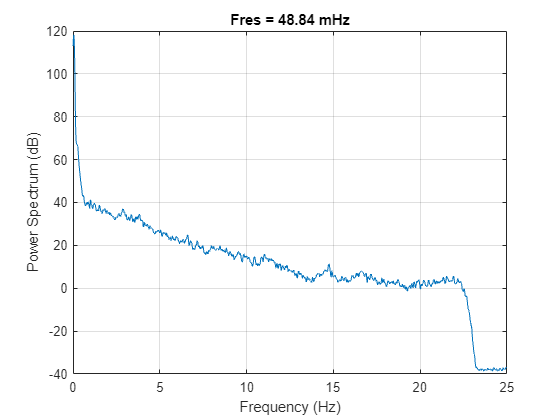

%psepectrum hace gráfica del espectro de potencia
%Realiza la transformada de Fourier internamente, hace valor
%absoluto de los resultados, eleva al cuadrado para la potencia
pspectrum(harp)

No se pueden observar picos significativos en el espectro de potencia. Las ondas de un terremoto que se propagan superficialmente tienen un rango de frecuencias bajas, por tanto la visualizacion de las ondas sismicas requieren de un zoom en las frecuencias bajas de la grafica. Para visualizar el rango espectral donde se produce la actividad sismica relevante, se pueden configurar los limites de las frecuencias donde queremos calcular el espectro de potencia.

`pspectrum``(``mysig``,``"FrequencyLimits"``,``[``a` `b``])`

**ACTIVIDAD**

Cree un nuevo espectro de potencia, pero configurando los limites del espectro entre `0` to `1 Hz`.

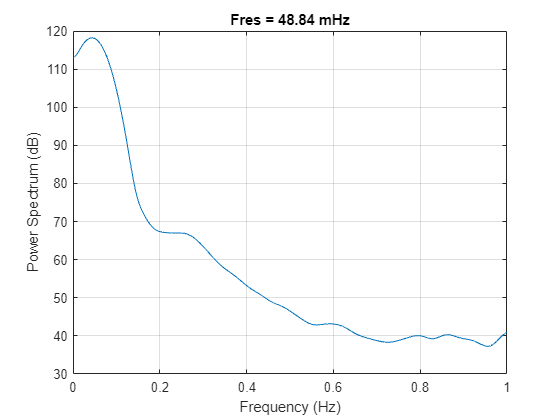

%Limitamos espectro a pequeñas frecuencias
pspectrum(harp,"FrequencyLimits",[0 1])

%Se observa un pico de potencia en 0.05 Hz, una onda con esa frecuencia
%llega de Sumatra a Alaka en el tiempo que ocurrió el terremoto y que llegó
%La señal se corresponde con el terremoto de Sumatra

Para estimar visualmente la frecuencia del pico, se puede deslizar el raton a lo largo de la grafica para visualizar los datos concretos. En la grafica ampliada se puede ver un pico alrededor de 0.05 Hz. Los geologos confirman que una onda con esta frecuencia recorre la distancia entre el origen del terremoto en Sumatra y las estaciones de medida en el lapso de tiempo que paso enrte el inicio del terremoto y el momento en el que se detecto en las estaciones de medida. Por tanto, esto confirma que esa componente espectral de baja frecuencia fue generada por el terremoto primario en Sumatra, y se propago por la corteza terrestre a grandes distancias. La siguiente grafica muesra este hecho:

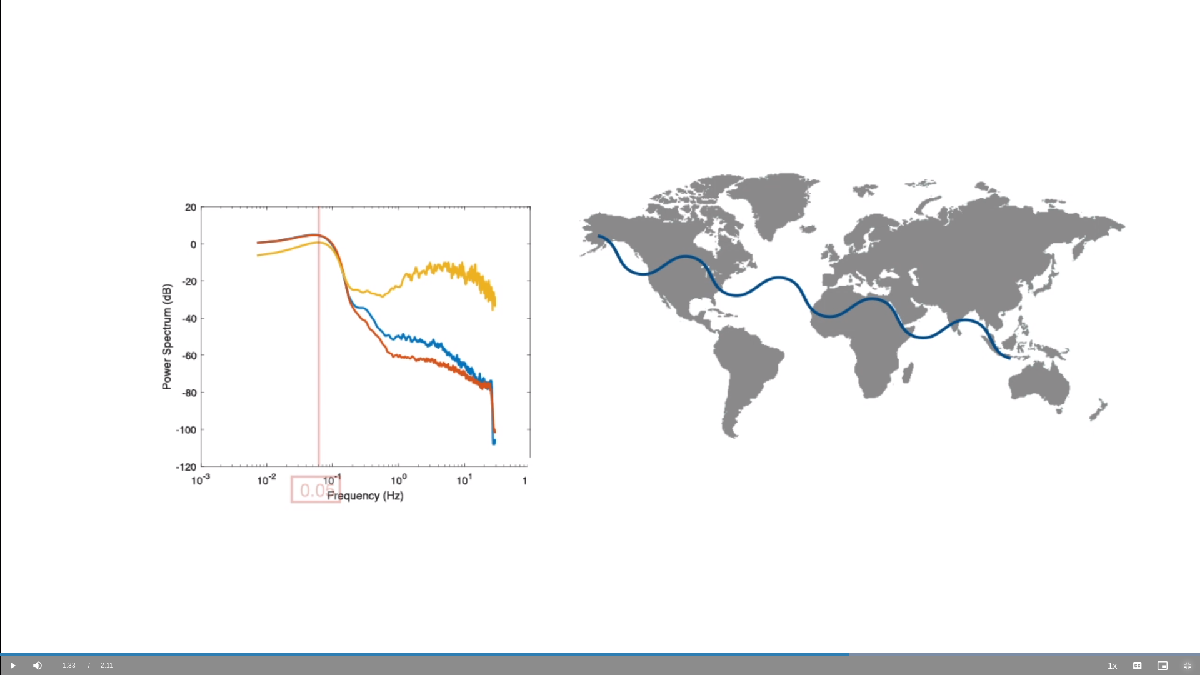

## Comparativa entre varias señales

El siguiente codigo permite importar las tres señales sismicas de las tres estaciones de medida consideradas: HARP, PAX, y monte Wrangell. 

Ts = readmatrix("seismicstation_ts.csv")

Ts =     0.0200    0.0200    0.0100


%Tablas temporales de cada sensor
harp = readtimetable("harp.csv","SampleRate",1/Ts(1));
pax = readtimetable("pax.csv","SampleRate",1/Ts(2));
wanc = readtimetable("wanc.csv","SampleRate",1/Ts(3));

Se pueden ver multiplies señales en la misma figura simplemente apilandolas.  Para crear una figura con multiples graficas apiladas es necesario definir el numero de graficas que se pretenden representar con la funcion `tiledlayout`, por ejemplo, una figura con una pila de dos filas y tres columnas de graficas se define con: 

`tiledlayout``(``2``,``3``)`

**ACTIVIDAD**

Cree una figura con tres filas y una coluna de graficas. 

%Para gráfica de varias subgráficas
tiledlayout(3,1); %Tres subgráficas

Para ir representando cada grafica en su lugar, use la funcion `nexttile`, como en el siguiente ejemplo:

`tiledlayout(2,3)`

`nexttile`

`plot(x,y)`

`nexttile`

`plot(x2,y2)`

**ACTIVIDAD**

A continaucion ejecute `nexttile` y represente `harp.Signal` respecto a `harp.Time`.  Añade el titulo `"HARP"`.

%Vamos cambiando de subgráfica
nexttile
plot(harp.Time,harp.Signal)
title("Harp");


**ACTIVIDAD**

Repite los pasos anteriores, para representar las señales correspondientes a `pax` y `wanc`. Usa los titulos `"PAX"` y `"WANC"`, respectivamente.

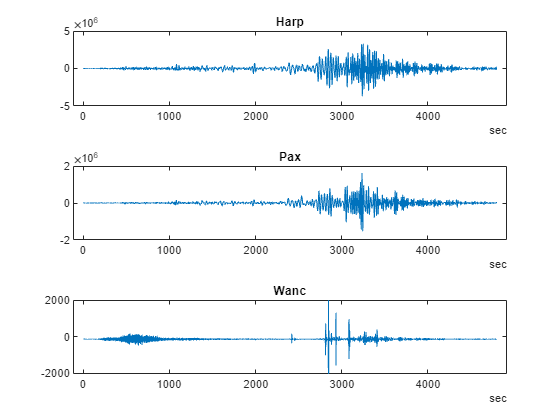

%Resto se subgráficas
nexttile
plot(pax.Time,pax.Signal)
title("Pax");
nexttile
plot(wanc.Time,wanc.Signal)
title("Wanc");

La señal del Monte Wrangell, WANC, parece muy diferente a las señales HARP y PAX. En el resto de la practica investigaremos las diferencias y similitudes entre ellas. Por el momento solo analizaremos el contenido espectral de las señales HARP y PAX, ya que son las que tienen la misma frecuencia de muestreo. Gracias a esto se pueden combiar en una misma tabla temporal de señales con un unico vector de tiempos mediante la funcion `synchronize:`

`tbl ``=` `synchronize``(``tbl1``,``tbl2``)`

**ACTIVIDAD**

Combine la señales `harp` y `pax` en una unica tabla temporal denominada `quakes, donde harp` es el primer parametro y `pax` es el segundo.

%Tabla temporal para harp y pax (tienen misma frecuencia de muestreo)
quakes = synchronize(harp,pax);

Ahora podemos calcular el espectro de potencia para la tabla temporal de señales. Para representar la grafica en una figura nueva use el comando `figure` antes de cualquier comando de representacion.

**ACTIVIDAD**

Represente en una figura nueva el espectro de potencia de la tabla temporal de señales denominada `quakes`. Represente unicamente las frecuencias en el intervalo `[``0` `1``]Hz`.

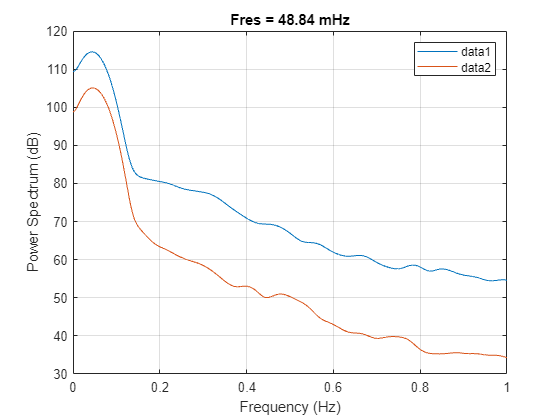

figure();
pspectrum(quakes,"FrequencyLimits",[0 1]);
legend;

Como se ha observado anteriormente, las señales HARP y PAX parecen similares en el dominio del tiempo, por tanto son similares en el dominio de la frecuencia. Como se ha comentado, las dos señales perciben correctamente las vibraciones del terremoto primario de Sumatra situado en la frecuencia de 0.05 Hz.

La señal del monte Wrangell tiene un periodo de muestreo diferente a las otras dos señales. A continuacion vamos a incorporar las tres señales en una sola tabla.

**ACTIVIDAD**

Combine las señales `harp`, `pax`, y `wanc`, en ese orden, y nombre la tabla resultante como `allquakes`. Visualice la tabla y vera que existen menos muestras en las señales HARP y PAX, ya que la frecuencia de muestreo es menor y las muestras que faltan se rellenan con `NaNs`.

%Tabla de todos los sensores
allquakes = synchronize(harp,pax,wanc)

allquakes = 480000×3 timetable
      Time      Signal_harp    Signal_pax    Signal_wanc
    ________    ___________    __________    ___________

    0 sec          -3094          389           -142    
    0.01 sec         NaN          NaN           -138    
    0.02 sec       -3108          391           -140    
    0.03 sec         NaN          NaN           -144    
    0.04 sec       -3126          402           -140    
    0.05 sec         NaN          NaN           -139    
    0.06 sec       -3149          407           -141    
    0.07 sec         NaN          NaN           -139    
    0.08 sec       -3172          409           -144    
    0.09 sec         NaN          N

En la siguiente seccion vamos a remuestrear la señal del monte Wrangell para evitar este problema. Por el momento, si intentamos calcular el espectro de potencia obtendremos un error, debido a la presencia de `NaNs`. Para ver el espectro de potencia de la señal `wanc` es necesario calcularlo individualmente, en vez de calcularlo a traves de toda la tabla denominada `allquakes`. Represente la densidad espectral de potencia de la señal `wanc.`

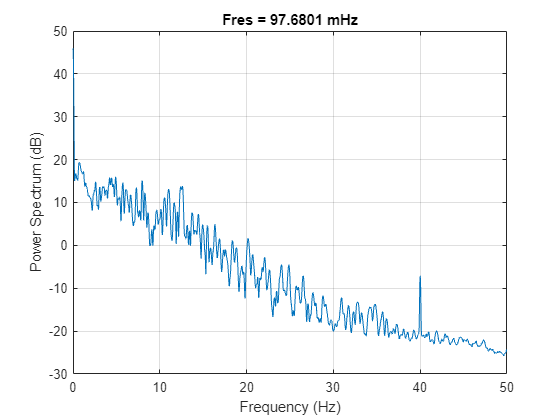

%Problema: Frecucencia de muestreo de wanc es distinta, necesario
%remuestrear para poder comparar señales

%Miramos espectro por separado
pspectrum(wanc);

## Uso de la aplicacion de analisis de señal

Mediante el siguiente codigo se abre una aplicacion para el analisis de señal y se importa la señal del monte Wrangell.

signalAnalyzer(wanc)

**ACTIVIDAD**

Con esta aplicacion se pueden reproducir muchos de los resultados obtenidos a traves de comandos, de un modo visual. En la pestaña **Display**, añada el espectro de la señal y mediante la herramienta **Panner** puede realizar zoom sobre las regiones de interes. Las tablas temporales correspondientes a HARP y PAX estan en el espcacio de trabajo, seleccionelas y arrastrelas a la ventana de visualizacion. En la pestaña **Spectrum** puede configurar la frecuencia maxima a 1 Hz, para poder visualizar claramente el contenido espectral de bajas frecuencias de las diferentes señales.

# Preprocesado

Como hemos comentado, la etapa de preprocesado puede incluir funciones como el remuestreo de señales, la normalizacion y el alineamiento. A continuacion analizamos por separado cada una de ellas.

## Remuestreo de señales

La funcion `resample` puede remuestrear señales que se han obtenido con un muestreo uniforme o no uniforme, para aproximarlas a una nueva señal con una nueva frecuencia de muestreo. Si la señal esta muestreada de un modo no uniforme, la funcion `resample` requiere un vector de tiempos que define el instante en el que sucede cada muestra. Las señales sismicas estan muestreadas uniformemente, asi que en este caso solo se requiere la señal a muestrar y los factores de remuestreo, `p` y `q`, que deben ser valores enteros. 

`y` `=` `resample``(``x``,``p``,``q``),`

La señal de salida tiene `p``/``q` muestras por cada muestra de entrada, `x`. Por ejemplo, el siguiente comando:

`y` `=` `resample``(``x``,``2``,``3``)`

remuestrea la señal `x` en un factor `2``/``3` de la frecuencia de muestreo original.

**ACTIVIDAD**

El vector que contiene el periodo de muestreo de las señales `Ts` se ha visualizado al principio, vuelva a visualizarlo y vera que el tercer elemento, correspondiente a la señal del monte Wrangell, tiene un periodo de muestreo menor, concretamente la mitad. Remuestre la señal `wanc` para que tenga la misma frecuencia de muestreo que `harp` y `pax`. Actualice el nombre de la variable de salida con el mismo nombre: `wanc`.

disp(Ts);

    0.0200    0.0200    0.0100



%Como el sensor wanc ha muestreado a una frecuencia mayor debemos
%remuestrearla (diezmado)
%Queremos remuestrear con factor de 1/2 (más lento) -> DIEZMADO
wanc = resample(wanc,1,2)

wanc = 240000×1 timetable
      Time      Signal 
    ________    _______

    0 sec       -105.05
    0.02 sec    -149.89
    0.04 sec    -136.71
    0.06 sec    -141.92
    0.08 sec     -141.2
    0.1 sec     -141.55
    0.12 sec     -138.6
    0.14 sec    -140.21
    0.16 sec    -142.53
    0.18 sec    -139.62
    0.2 sec      -133.1
    0.22 sec    -140.89
    0.24 sec    -141.44
    0.26 sec    -138.09
    0.28 sec    -136.64
    0.3 sec     -141.46


%Ha filtrado la señal de diezmado, para no coger justo los puntos en los
%que hay variación (mejor aproximación)

Con el objetivo de comparar las tres señales con el mismo periodo de muestreo, hemos reducido la frecuencia de muestreo de `wanc` mediante un diezmado o "downsampling" de la señal, de modo que corresponda con la frecuncia de muestreo de `harp` y `pax.` `En` lugar de ello, podriamos haber remuestrado las otras dos señales para hacerlas coincidir con `wanc`. Para ello, volvemos a cargar el periodo de muestreo junto con las señales originales:

Ts = readmatrix("seismicstation_ts.csv")

Ts =     0.0200    0.0200    0.0100


harp = readtimetable("harp.csv","SampleRate",1/Ts(1));
pax = readtimetable("pax.csv","SampleRate",1/Ts(2));
wanc = readtimetable("wanc.csv","SampleRate",1/Ts(3));

**ACTIVIDAD**

Repita la tarea anterior utilizando la funcion `resample` para aumentar la frecuencia de muestreo, realizando una interpolacion de las señales `harp` y `pax`, de modo que correspondan con la frecuencia de muestreo de `wanc`. Finalmente, cree una una tabla conjunta con las tres señales.

%En vez de bajar la frecuencia de wanc, podemos subir (al doble) la
%frecuencia de muestreo de harp y pax (disponemos de los datos) ->
%INTERPOLACIÓN
harp = resample(harp,2,1); 
pax = resample(pax,2,1);
allquakes = synchronize(harp,pax,wanc)

allquakes = 489429×3 timetable
      Time      Signal_harp    Signal_pax    Signal_wanc
    ________    ___________    __________    ___________

    0 sec         -3095.6         389.2         -142    
    0.01 sec      -3511.5        440.73         -138    
    0.02 sec      -3109.6         391.2         -140    
    0.03 sec      -2903.9        369.21         -144    
    0.04 sec      -3127.6        402.21         -140    
    0.05 sec      -3266.4        422.28         -139    
    0.06 sec      -3150.6        407.21         -141    
    0.07 sec      -3077.1        396.61         -139    
    0.08 sec      -3173.6        409.21         -144    
    0.09 sec      -3239.6        41

En esta tabla y en la anterior puede comprobar que el periodo de muestreo es el adecuado.

## Normalizacion

A continuacion visualizamos otra vez las tres señales:

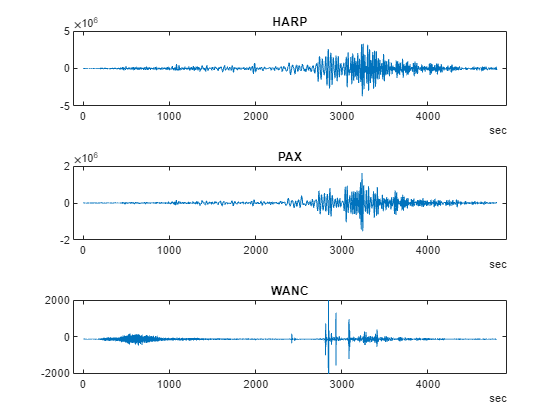

tiledlayout(3,1)
nexttile
plot(harp.Time,harp.Signal)
title("HARP")
nexttile
plot(pax.Time,pax.Signal)
title("PAX")
nexttile
plot(wanc.Time,wanc.Signal)
title("WANC")

En esta ocasion nos interesa analizar los valores de la amplitud de las señales, para ello visualice los limites del eje vertical de las tres señales. Las señales HARP y PAX son mucho mas grandes que la señal del monte Wrangell. En esta aplicacion, las amplitudes de las señales no son relevantes, asi que es mas facil establecer comparativas si las tres señales se normalizan. La funcion `normalize` se encarga de normalizar la tabla temporal de señales:

`tbl` `=` `normalize``(``tbl``)`

Por defecto, la funcion de normalizacion usa el metodo [z-score](https://www.mathworks.com/help/matlab/ref/double.normalize.html#mw_e6886c44-2923-4074-844a-f3e1a447359d), el cual normaliza la varianza y resta la media de la señal.

**ACTIVIDAD**

Normalice las tres señales y reasigne las señales normalizadas con el mismo nombre, tal y como se ha mostrado en el comando anterior. 

%Necesario normalizar señales para comparar amplitudes (diferencias por
%sensor) -> Deben parecerse porque las tres están en Alaska
allquakes = normalize(allquakes)

allquakes = 489429×3 timetable
      Time      Signal_harp    Signal_pax    Signal_wanc
    ________    ___________    __________    ___________

    0 sec        0.0013974     -0.0015601     -0.034574 
    0.01 sec    0.00066986     -0.0012954      0.037226 
    0.02 sec     0.0013729     -0.0015498     0.0013263 
    0.03 sec     0.0017328     -0.0016628     -0.070474 
    0.04 sec     0.0013414     -0.0014933     0.0013263 
    0.05 sec     0.0010985     -0.0013902      0.019276 
    0.06 sec     0.0013011     -0.0014676     -0.016624 
    0.07 sec     0.0014297     -0.0015221      0.019276 
    0.08 sec     0.0012609     -0.0014573     -0.070474 
    0.09 sec     0.0011456     -0.0

Ahora las tres señales tienen el mismo indice temporal y amplitudes similares. En ocasiones, la normalizacion contribuye a simplificar el analisis posterior de las señales.

## Alineamiento

Las tres estaciones de medida estan situadas en diferentes puntos de Alaska y las ondas sismicas superficiales se han originado y han viajado desde Indonesia, lo cual hace que las ondas lleguen a las diferentes estaciones en diferentes momentos. La distancia fisica entre estaciones de medida genera un retardo (`lag)` entre las señales registradas, tal y como se puede ver ejecutando el siguiente codigo:

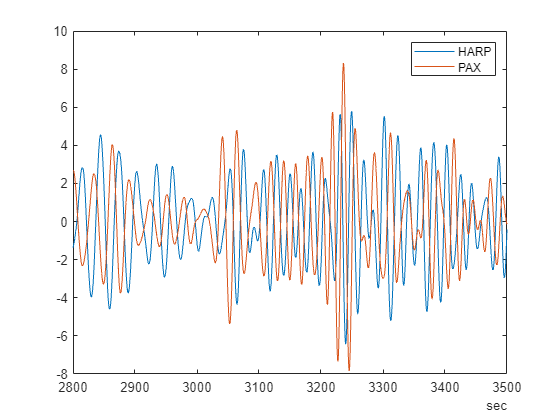

%Importacion de señales
Ts = readmatrix("seismicstation_ts.csv");
harp = readtimetable("harp.csv","SampleRate",1/Ts(1));
pax = readtimetable("pax.csv","SampleRate",1/Ts(2));
wanc = readtimetable("wanc.csv","SampleRate",1/Ts(3));
%Remuestreo y normalizacion 
wanc = timetable(harp.Time,resample(wanc.Signal,1,2),'VariableNames',"Signal");
harp = normalize(harp);
pax = normalize(pax);
wanc = normalize(wanc);
%Representacion grafica
figure
plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

Como se puede observar, la señal `harp` y `pax` tienen cierta similaridad y un retardo relativo entre ellas. La correlacion cruzada se suele utilizar para medir la similitud entre una señal y una copia desplazada en el tiempo. La correlacion cruzada entre dos señales es una variante de la convolucion, en la cual la señal deslizante no se invierte, la expresion matematcia es:


$${\displaystyle y[n]  \equiv f[n]\star g[n] \equiv \sum _{m=-\infty }^{\infty }{\ {f[m]}}g[m+n]}$$


La posicion $n$, en la cual las dos señales son coincidentes, genera un maximo en la correlacion y el indice en el que se produce el maximo corresponde a la separacion relativa entre las dos señales, en unidades de muestras. En condiciones ideales, los tres sismografos deberian registrar la misma señal con un cierto retardo temporal, que es la señal que se origina en el terremoto de Sumatra, pero en realidad las tres señales tienen ruido y ciertas distorsiones que las hacen diferentes. Aun asi, el metodo de corelacion cruzada funciona bastante bien aunque las señales no sean copias exactas, siempre que tengan una cierta similitud en su comportamiento. Una vez que tenemos la correlacion cruzada, la funcion `finddelay` usa la correlacion cruzada para estimar el retardo entre señales, en esta seccion utilizaremos esta funcion para alinear las señales. Dado que las tres estaciones sísmicas deberían haber registrado las mismas ondas superficiales, podemos por ejemplo correlacionar la señal del Monte Wrangell con las señales HARP y PAX. La correlación cruzada permite determinar si la señal registrada en la estación del Monte Wrangell tiene elementos comunes con las otras estaciones sísmicas. Para correlacionar señales, utilizamos la función `xcorr`.

`[``c``,``lags``]` `=` `xcorr``(``x``,``y``)`

**ACTIVIDAD**

Calcule la correlación cruzada de `harp.Signal` y `wanc.Signal`. Utilice dos salidas denominadas `c` y `lags`, respectivamente.

%Llegada de las vibraciones en distintos momentos porque tarda en llegar
%Se debe tratar de la misma onda, utilizamos correlación para encontrar nº
%de muestras retardadas y así alinear las señales
[c,lags] = xcorr(harp.Signal,wanc.Signal)

**ACTIVIDAD**

Cree un gráfico con los retardos en el eje `x` y la correlacion `c` en el eje `y`.

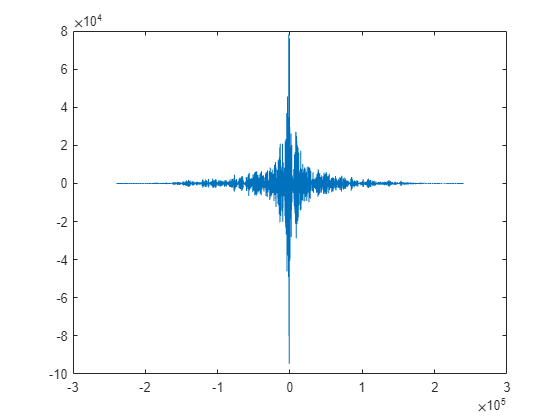

plot(lags,c)

%El pico indica para que lag hay más correlación (mucha correlación). Vemos que para 0 segundos
%están muy correlacionadas, por lo que no tienen retardo.

El pico más significativo en el gráfico se encuentra cerca del origen, lo cual indica un desplazamiento reducido. La presencia de un pico es un indicador de que existe una coincidencia entre señales y en ese caso se puede encontrar el retardo entre las señales, el cual coincide con la posicion en la que se alcanza el pico. Si existe una correlación suficiente entre dos señales, la función `finddelay` estima el retardo relativo entre ellas.

`d` `=` `finddelay``(``x``,``y``)`

Las señales de entrada `x` e `y` deben ser vectores, no tablas temporales. La salida `d` es el número de muestras correspondiente al retardo.

**ACTIVIDAD**

Estime el retardo entre `harp.Signal` y `wanc.Signal`, asignando la salida a la variable` harpDelay`.

%Si hay mucha correlación, podemos decir que es misma señal retardada
harpDelay = finddelay(harp.Signal,wanc.Signal)

harpDelay = 1169

`harpDelay` es el retardo entre señales medido en número de muestras. Para hallar el retardo en segundos es necesario multiplicar las muestras por el periodo de muestreo.

**ACTIVIDAD**

Multiplique `harpDelay` por el primer elemento del vector de periodos de muestreo `Ts`. Reasigne la salida de nuevo a `harpDelay`.  A continuación, convierta `harpDelay` a segundos con la función `seconds`. 

%1169 muestras de delay. Muy pocas respecto al total de muestras (casi 0
%segundos de delay)
%Para pasar a segundos multiplicamos muestras por el periodo de muestreo
%(s/muestras)
harpDelay = seconds(harpDelay*Ts(1))

harpDelay = duration
   23.38 sec


%Es la misma señal pero con un retraso de 23.38 segundos! Mismos patrones
%de comportamiento aunque no se parezcan visualmente

Ha calculado el retardo entre las señales HARP y monte Wrangell!, a pesar de que las señales son visualmente muy diferentes. Esto quiere decir que ambas señales contienen patrones de comportamiento similar, aunque no se aprecie visualmente!. Ademas, los geólogos confirman que el retardo obtenido es correcto, utilizando la velocidad de propagacion de las ondas sísmicas y la distancia entre las dos estaciones. ¿Cómo deberíamos modificar la tabla temporal para alinear las señales y comparar los eventos sismicos? Podría añadir el retardo temporal en la variable `Time` correspondiente a la señal `harp`, pero es más eficiente  establecer la propiedad `StartTime` en la tabla temporal. Puede establecer las propiedades de la tabla temporal usando la nomenclatura basada en punto:

`tbl.Properties.``PropName`

**ACTIVIDAD**

Establezca la propiedad `StartTime` de la tabla temporal `harp` para que comience en el instante `harpDelay`.

%Vamos a enseñar muestras de Harp 23.38 segundos después para así alinear
%con wanc (23.38 es nuevo origen)
harp.Properties.StartTime = harpDelay

harp = 240000×1 timetable
      Time         Signal  
    _________    __________

    23.38 sec     0.0014001
    23.4 sec      0.0013756
    23.42 sec     0.0013442
    23.44 sec     0.0013039
    23.46 sec     0.0012637
    23.48 sec     0.0012077
    23.5 sec      0.0011412
    23.52 sec     0.0010712
    23.54 sec     0.0010013
    23.56 sec    0.00093303
    23.58 sec     0.0008613
    23.6 sec     0.00079832
    23.62 sec    0.00073708
    23.64 sec     0.0006846
    23.66 sec    0.00063561
    23.68 sec    0.00059363


%También se pdría con timetable(.,.,'StartTime',harpDelay)

Como se puede ver, la tabla temporal ahora comienza en 23.38 segundos. Para ver si las señales `HARP` y `PAX` estan alineadas, puede representar ambas señales en el mismo gráfico.

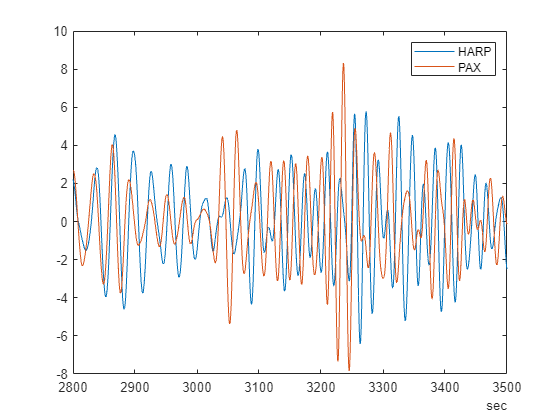

figure;
plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

Compárelo con la grafica inicial de la seccion "Alineamiento": ¿Parecen más alineadas?. Observese que no hemos alineado HARP con PAX, sino que hemos alineado HARP con WANC y, sin embargo, HARP y PAX parecen alineadas. Esto es porque la distancia entre HARP y PAX es similar que la que hay entre HARP y WANC!!!!!. Para comparar la señal HARP con la señal `WANC`, que son las que estan realemente alineadas, tendremos que filtrarla primero, ya que la presencia de altas frecuencias no deja ver el desplazamiento, de hecho no parecen tener ningun patron de comportamiento comun!.

**ACTIVIDAD**

Repite la tarea anterior, pero esta vez alinee la señal PAX con la señal WANC. Para ello tenga en cuenta que el periodo de muestreo de PAX es el segundo elemento de `Ts`.

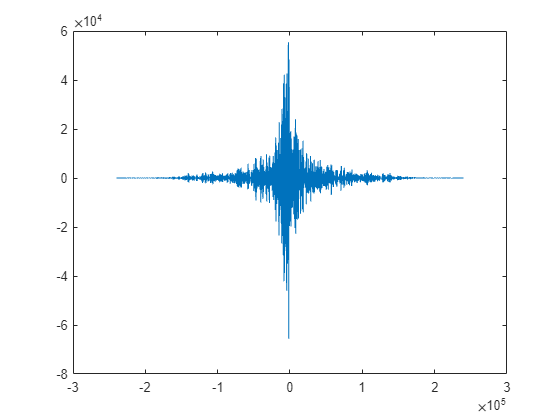

%Alineamiento entre pax y wanc
[c,lags] = xcorr(pax.Signal,wanc.Signal);
plot(lags,c)

%Hay mucha correlación, por lo que hay un delay entre las señales iguales
paxDelay = finddelay(pax.Signal,wanc.Signal);
paxDelay = seconds(paxDelay*Ts(2))

paxDelay = duration
   35.54 sec


pax.Properties.StartTime = paxDelay

pax = 240000×1 timetable
      Time         Signal  
    _________    __________

    35.54 sec    -0.0015611
    35.56 sec    -0.0015509
    35.58 sec    -0.0014944
    35.6 sec     -0.0014687
    35.62 sec    -0.0014584
    35.64 sec    -0.0014173
    35.66 sec    -0.0014019
    35.68 sec    -0.0013814
    35.7 sec     -0.0013454
    35.72 sec      -0.00133
    35.74 sec    -0.0013146
    35.76 sec    -0.0012632
    35.78 sec    -0.0012632
    35.8 sec     -0.0012427
    35.82 sec    -0.0011913
    35.84 sec    -0.0011862


Fijese que el retardo en este caso es de 35.54 segundos respecto de los 23.38 segundos en el caso anterior.

## Combinacion de tablas temporales

Utilizando el siguiente codigo, las señales se importan y se preprocesan segun hemos visto:

% importacion de señales
Ts = readmatrix("seismicstation_ts.csv");
harp = readtimetable("harp.csv","SampleRate",1/Ts(1));
pax = readtimetable("pax.csv","SampleRate",1/Ts(2));
wanc = readtimetable("wanc.csv","SampleRate",1/Ts(3));
% remuestreo y normalizacion 
wanc = timetable(harp.Time,resample(wanc.Signal,1,2),'VariableNames',"Signal");
harp = normalize(harp);
pax = normalize(pax);
wanc = normalize(wanc);
% Alineamiento de señales
harp.Properties.StartTime = seconds(finddelay(harp.Signal,wanc.Signal)*Ts(1));
pax.Properties.StartTime = seconds(finddelay(pax.Signal,wanc.Signal)*Ts(2));

A continuacion podemos combinarlas en una tabla temporal con la función synchronize.

**ACTIVIDAD**

Sincronice las señales de `harp`, `pax` y `wanc` en ese orden. Nombra la nueva tabla temporal como "`quakes"`.

%Todas las señales en una tabla
quakes = synchronize(harp,pax,wanc)

quakes = 241777×3 timetable
      Time      Signal_harp    Signal_pax    Signal_wanc
    ________    ___________    __________    ___________

    0 sec           NaN           NaN           0.62923 
    0.02 sec        NaN           NaN          -0.17635 
    0.04 sec        NaN           NaN          0.060341 
    0.06 sec        NaN           NaN         -0.033099 
    0.08 sec        NaN           NaN         -0.020248 
    0.1 sec         NaN           NaN         -0.026485 
    0.12 sec        NaN           NaN          0.026396 
    0.14 sec        NaN           NaN        -0.0024316 
    0.16 sec        NaN           NaN         -0.044034 
    0.18 sec        NaN           NaN 

%Tener en cuenta que las señales harp y pax no empiezan hasta su retardo
%(Estamos cogiendo como referencia la estación wanc para ver todas como
%misma señal)

Los nuevos nombres de las variables son `Signal_harp`, `Signal_pax` y `Signal_wanc`. Puede actualizar la propiedad `VariableNames` de la tabla para elegir nombres más concisos.

`tbl.Properties.VariableNames` `=` `[``"Name1"` `"Name2"``]`

**ACTIVIDAD**

Actualice los nombres de las variables almacenadas en quakes a `HARP`, `PAX` y `WANC`.

quakes.Properties.VariableNames = ["HARP" "PAX" "WANC"]

quakes = 241777×3 timetable
      Time      HARP    PAX       WANC   
    ________    ____    ___    __________

    0 sec       NaN     NaN       0.62923
    0.02 sec    NaN     NaN      -0.17635
    0.04 sec    NaN     NaN      0.060341
    0.06 sec    NaN     NaN     -0.033099
    0.08 sec    NaN     NaN     -0.020248
    0.1 sec     NaN     NaN     -0.026485
    0.12 sec    NaN     NaN      0.026396
    0.14 sec    NaN     NaN    -0.0024316
    0.16 sec    NaN     NaN     -0.044034
    0.18 sec    NaN     NaN     0.0081566
    0.2 sec     NaN     NaN       0.12536
    0.22 sec    NaN     NaN     -0.014648
    0.24 sec    NaN     Na

Tenga en cuenta que los nombres de las variables distinguen entre mayúsculas y minúsculas. La función `stackedplot` es una forma práctica de visualizar múltiples variables en una tabla temporal.

`stackedplot``(``tbl``)`

**ACTIVIDAD**

Cree un gráfico apilado de la tabla de terremotos.

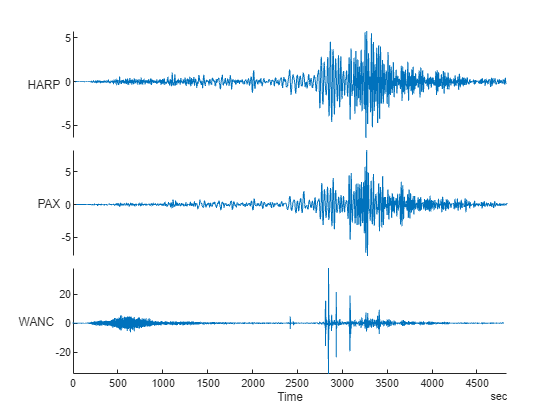

%Forma rápida de graficar todas las señales de una
stackedplot(quakes)

Dado que las señales `HARP` y `PAX` comienzan más tarde que la señal `WANC`, los inicios de `HARP` y `PAX` contienen `NaNs`. Del mismo modo, el final de las señales `HARP` y `WANC` contiene `NaNs`. Funciones como `pspectrum` no se ejecutarán si las señales de entrada tienen `NaNs`. En este caso, la solución más natural es recortar los inicios y finales de las señales. Recuerde que puede utilizar la función `timerange` para extraer un segmento de una tabla temporal.

`tr` `=` `timerange``(``seconds``(``st``)``,``seconds``(``en``))`

`tbl` `=` `tbl``(``tr``,:``)`

**ACTIVIDAD**

Cree una nueva tabla llamada `quakesROI` que contenga el intervalo de tiempo entre `2800-3500` segundos de las señales contenidas en `quakes`.  A continuación, crea un gráfico apilado de `quakesROI`.

%Cogemos sólo región de interés (ROI), donde hay muestras (alineadas)
roi = timerange(seconds(2800),seconds(3500));
quakesROI = quakes(roi,:)

quakesROI = 35000×3 timetable
       Time        HARP      PAX        WANC   
    __________    ______    ______    _________

    2800 sec       2.203    2.2422     -0.14834
    2800 sec      2.2008    2.2448    -0.094129
    2800 sec      2.1986    2.2469     -0.11828
    2800.1 sec    2.1961    2.2489     -0.21078
    2800.1 sec    2.1938     2.251     -0.38239
    2800.1 sec    2.1915     2.253     -0.39148
    2800.1 sec    2.1893    2.2552      -0.4271
    2800.1 sec    2.1871    2.2573       -0.566
    2800.2 sec    2.1848    2.2594     -0.61011
    2800.2 sec    2.1824    2.2612     -0.57063
    2800.2 sec    2.1799    2.2631     -0.52244
    2800.2 sec

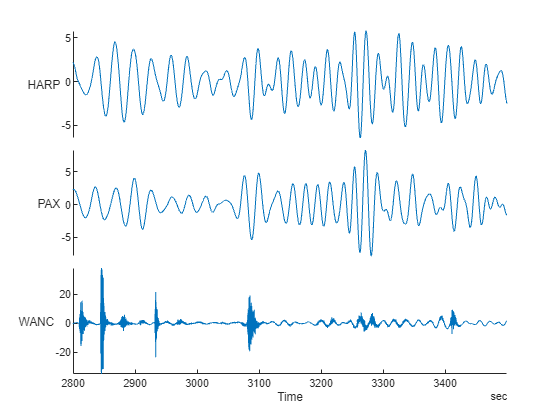

%Graficamos
stackedplot(quakesROI)

En el resto de la practica, en lugar de cargar las ondas sísmicas desde sus archivos csv, utilizaremos la tabla temporal de terremotos que acabamos de definir, limitada al rango temporal de 2800-3500 segundos. 

# Analisis espectral

Segun la grafica anterior, el comportamiento temporal de las señales HARP y PAX es similar, mientras que en la señal WANC se puede ver una dinamica con oscilaciones mucho mas rapidas, lo cual implica la presencia de componentes espectrales de alta frecuencia. Un zoom de las tres señales se puede ver en la siguiente figura:

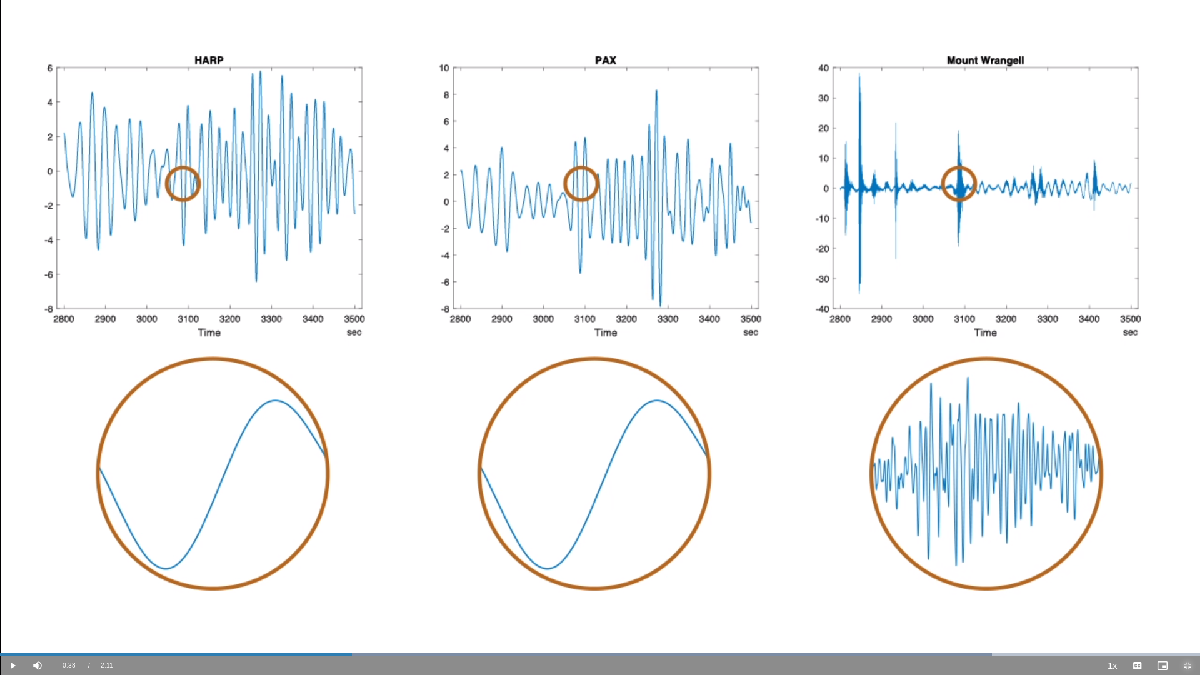

La estacion WANC ha registrado movimientos de alta frecuencia que las otras estaciones no han registrado, es probable que este pasando "algo", sin embargo, en el dominio del tiempo no se puede extraer mas informacion. Tal y como se ha visto anteriormente, si llamamos a la función `pspectrum` sin ninguna salida se representara el espectro de potencia, tal y como se puede ver en el siguiente codigo:

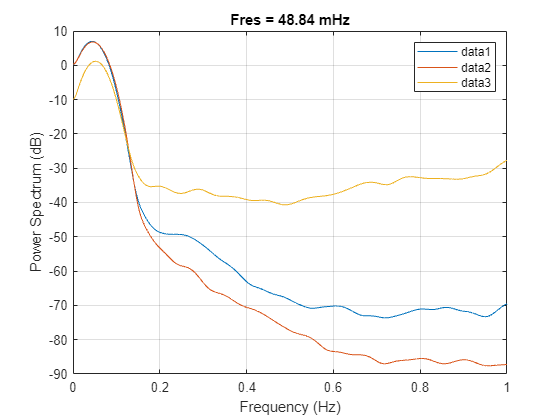

load quakes
pspectrum(quakes,"FrequencyLimits",[0 1])
legend

La visualización por defecto funciona para muchas aplicaciones, pero en aplicaciones sismológicas es común utilizar el eje `x` logarítmico. Para personalizar los gráficos de espectro de potencia puede obtener los valores del espectro y las frecuencias correspondientes como salidas de la función `pspectrum:`

`[``pwr``,``freq``]` `=` `pspectrum``(``tbl``)`

Si `tbl` contiene varias señales, `pwr` es una matriz en la que cada columna es el espectro de cada señal.

**ACTIVIDAD**

Calcule el espectro de potencia de las señales almacenadas en `quakes`. Nombra las salidas `p` y `f`, respectivamente

[p,f] = pspectrum(quakes)

p =     1.0515    1.0750    0.1016
    1.2200    1.2221    0.1297
    1.7010    1.6453    0.2148
    2.4210    2.2885    0.3570
    3.2595    3.0544    0.5502
    4.0625    3.8118    0.7764
    4.6700    4.4167    1.0034
    4.9543    4.7462    1.1898
    4.8555    4.7324    1.2959
    4.3983    4.3807    1.2974


f =          0
    0.0061
    0.0122
    0.0183
    0.0244
    0.0305
    0.0366
    0.0427
    0.0488
    0.0549


%Columnas de p son los espectros de cada señal
%f son las frecuencias

La función `semilogx` creará un gráfico donde el eje horizontal se representa en escala logarítmica.

**ACTIVIDAD**

Crea un gráfico semilogaritmico en el eje `x`, donde se representan las frecuencias, `f,` en el eje `x` y la potencia espectral, `p,` en el eje `y`.

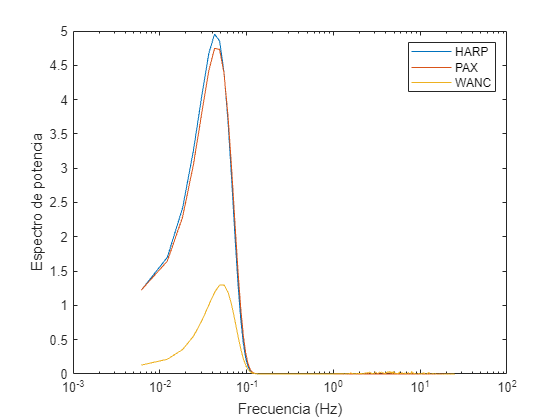

%Gráfica con eje horizontal en escala logarítmica
semilogx(f,p)
xlabel("Frecuencia (Hz)")
ylabel("Espectro de potencia")
legend("HARP","PAX","WANC")

Ahora podemos ver claramente los picos de baja frecuencia en las señales, pero todavía necesitamos modificar el eje `y`. Observe que el primer gráfico del script tiene "Espectro de potencia (dB)" en el nombre del eje vertical. Normalmente se utiliza una escala de dB para visualizar los espectros de potencia calculando `10log10(p)`, donde p es la densidad espectral de potencia. Puedes usar directamente` 10*log10(p)`, o puedes usar la función `db` para hacer el mismo cálculo, con la opcion "`power`".

`db(p, "power")`

**ACTIVIDAD**

Vuelva a crear el gráfico semilogarítmico, pero esta vez utilice unidades `dB` en el eje `y`. Añade al gráfico las etiquetas en los ejes y una leyenda adecuadas, con los nombres de las señales. Cuando cree la leyenda, recuerde que el orden de las señales en los seísmos es: `HARP`, `PAX`, `WANC`.

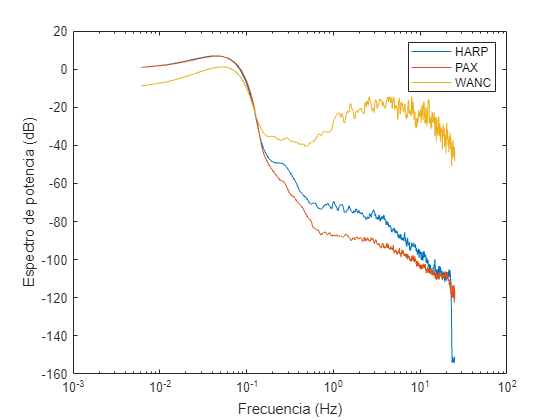

%Mismo gráfico pero en decibelios (10*log10(p))
semilogx(f,db(p,"power"))
xlabel("Frecuencia (Hz)")
ylabel("Espectro de potencia (dB)")
legend("HARP","PAX","WANC")

%Wanc tiene componentes de altas frecuencias, debe ser de otros terremotos
%secuandarios que aparecen y desaparecen muy rápido (altas frecuencias),
%las otras estaciones no los captaron

Ahora puedes comparar fácilmente el espectro de potencia de la señal sísmica de cada estación. Las tres señales tienen un comportamiento de bajas frecuencias similar, salvo un factor de escala. En la grafica se puede ver un pico alrededor de 0.05 Hz. Como se ha comentado, los geologos confirman que una onda con esta frecuencia recorre la distancia entre el origen del terremoto en Sumatra y las estaciones de medida en el lapso de tiempo que pasa enrte el inicio del terremoto y el momento en el que se detecta en las estaciones. Por tanto, esto confirma que esa componente espectral de baja frecuencia se origino con el terremoto primario en Sumatra, y es la que se propaga por la corteza terrestre a grandes distancias. La siguiente grafica muestra este hecho:

Por otro lado, resulta muy claro, que la señal de la estación del monte Wrangell contiene un contenido significativo de altas frecuencias, responsable de las fuertes oscilaciones en el dominio temporal. Al corresponder a frecuencias altas, estas oscilaciones no pueden provenir del terremoto primario de Sumatra, sino que deben proceder de terremotos secundarios muy cercanos a la estacion del monte Wrangell, tan debiles que no los detectaron las otras estaciones. Las frecuencias altas deben provenir de terremotos cercanos, ya que se desvanecen muy rapidamente en la propagacion por la corteza terrestre. Ahora, la pregunta es si esos terremotos secundarios pudieron ser originados por el terremoto primario de Sumatra o son fenomenos independientes. 

En la siguiente seccion filtraremos la señal del Monte Wrangell para mantener sólo el contenido de baja frecuencia, para ver si el contenido espectral de bajas frecuencias coincide con las señales PAX y HARP, y por tanto es el originado por el terremoto primario de Sumatra. De este modo aislamos el contenido espectral de bajas frecuencias, el cual deberia ser similar en las tres señales. Por otro lado, analizaremos el contenido espectral de altas frecuencias de la señal WANC, que da cuenta de otros movimientos sismicos de caracter muy cercano pero que estan alineados con los movimientos sismicos primarios en Sumatra.

## Espectrograma

Un espectrograma es una representacion del espectro de frecuencias de una señal segun evoluciona en el tiempo. Para obtenerlo, se calcula el espectro de la señal en una ventana de dimensiones reducidas que se va deslizando a lo largo de la propia señal. En cada posicion de la ventana tenemos un espectro y el deslizamiento completo de la ventana da lugar a una sucesion de espectros que forman una imagen bidimensional tiempo-frecuencia, donde el eje horizontal es la posicion de la ventana (en unidades de tiempo) y en el eje vertical se representa el espectro, o densidad espectral de potencia, en unidades de potencia o decibelios. Este analisis espectral contempla tanto la dimension temporal (posicion de la ventana) como la dimension espectral (transformada de Fourier en la ventana), y por ello se llama STFT, Short Time Fourier Spectrum. Ademas de visualizar el contenido espectral de la señal, nos informa de su evolucion en el tiempo (vista a traves de la ventana). Antes de filtrar la señal, crearemos un espectrograma de la señal del Monte Wrangell para investigar el espectro más a fondo. En primer lugar vamos a cargar los datos:

load quakes
quakes

quakes = 35000×3 timetable
       Time        HARP      PAX        WANC   
    __________    ______    ______    _________

    2800 sec       2.203    2.2422     -0.14834
    2800 sec      2.2008    2.2448    -0.094129
    2800 sec      2.1986    2.2469     -0.11828
    2800.1 sec    2.1961    2.2489     -0.21078
    2800.1 sec    2.1938     2.251     -0.38239
    2800.1 sec    2.1915     2.253     -0.39148
    2800.1 sec    2.1893    2.2552      -0.4271
    2800.1 sec    2.1871    2.2573       -0.566
    2800.2 sec    2.1848    2.2594     -0.61011
    2800.2 sec    2.1824    2.2612     -0.57063
    2800.2 sec    2.1799    2.2631     -0.52244
    2800.2 sec

Puede crear un espectrograma con la función `pspectrum` incluyendo la opcion "`spectrogram`". Sólo puede crear el espectrograma de una señal a la vez, pero la tabla de terremotos contiene tres señales. Puede utilizar la indexación por punto para proporcionar la señal y los vectores temporales por separado.

`pspectrum(datos.Signal,datos.Time, "`spectrogram`")`

**ACTIVIDAD**

Cree un espectrograma de la señal del Monte Wrangell que esta contenida en la tabla quakes.

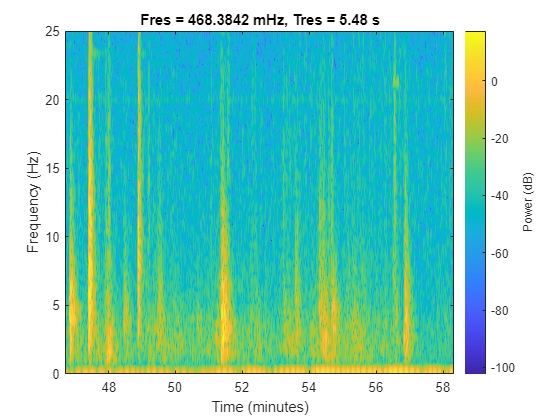

%Espectrograma de wanc (evolución temporal de la señal en frecuencias)
%quakes es tabla de tres señales y un tiempo
pspectrum(quakes.WANC,quakes.Time, "spectrogram")

En el espectrograma puede verse la presencia de bandas de alta frecuencia. Los instantes temporales en los que se intensifican estas bandas se corresponden con los terremotos locales cercanos a la estación sísmica del monte Wrangell. La mayoría de los temblores originados por terremotos locales contienen frecuencias mas altas que los lejanos, ya que las frecuencias mas altas son las que mas se atenuan en la propagacion. En particular, los terremotos cercanos contienen frecuencias entre 2 Hz y 10 Hz. Esta banda se hará más evidente realizando un zoom en ese rango de frecuencias. Al crear el espectrograma, puede especificar un rango de frecuencias con la opción "FrequencyLimits". 

`pspectrum(datos, "espectrograma", ...`

`    "FrequencyLimits",[a b])`

**ACTIVIDAD**

Repita el comando anterior, pero esta vez, establezca los límites de frecuencia de 2 Hz a 10 Hz.

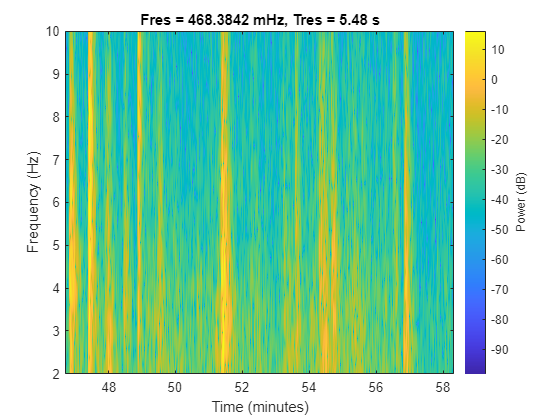

%Donde hay colores vivos es cuando tiene mayor potencia
%Limitamos espectograma de 2 a 10 Hz (altas frecuencias)
%para ver cuando terremotos locales (Sumatra es de 0.05 Hz)
pspectrum(quakes.WANC,quakes.Time, "spectrogram","FrequencyLimits",[2 10])

Ahora las bandas amarillas son más prominentes. Sin embargo, sigue habiendo mucho ruido de fondo. Observe que la barra de color pasa de azul oscuro a amarillo, pero no se ve azul oscuro en el espectrograma, esto sucede porque son puntos aislados que pueden provenir de ruido local. Puedes eliminar las frecuencias que tienen poca potencia utilizando la opción "`MinThreshold`".

`pspectrum(datos, "espectrograma", ...`

`    "MinUmbral",n) `

El fondo del espectrograma tiene mucho verde, por lo que resulta interesante utilizar el verde como umbral.

**ACTIVIDAD**

Repita el comando anterior, pero esta vez establezca el límite inferior de la potencia en -50 decibelios (dB).

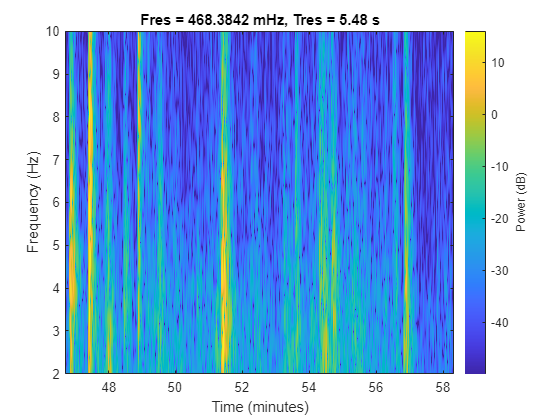

%Ver sólo componentes con alta potencia (de -50 a arriba)
pspectrum(quakes.WANC,quakes.Time, "spectrogram","FrequencyLimits",[2 10],"MinThreshold",-50)

Ahora el espectrograma contiene más detalles, aunque el área alrededor de las bandas sigue siendo bastante ruidosa. 

# Filtrado

Como hemos estudiado, un filtro es un sistema LTI que modifica el contenido espectral de la señal de entrada de forma multiplicativa. La respuesta en frecuencia del filtro puede potenciar o atenuar las frecuencias del espectro que nos interese, en cada aplicacion concreta. Para definir un filtro es necesario definir las bandas de frecuencia que vamos a dejar pasar, las que vamos a atenuar y un cierto margen de frecuencias de transicion entre ambas. En la siguiente figura se puede ver la distribucion de bandas en un filtro paso-bajo:

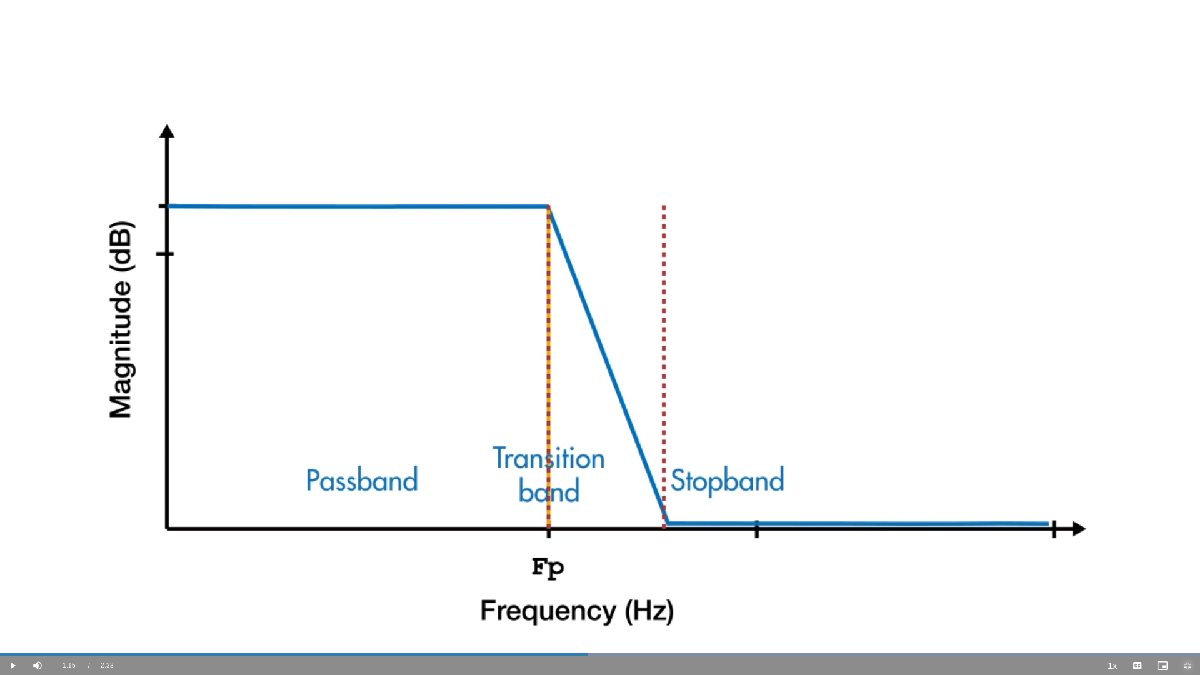

La anchura de la banda de transicion viene definida por un parametro denominado "steepness", y cuando mayor es el parametro mas abrupto es el cambio entre banda de paso y banda eliminada. Un filtro muy abrupto requiere un orden alto y mucha complejdad computacional, luego es interesante llegar a un compromiso razonable segun la aplicacion. 

En nuestra aplicacion, las frecuencias bajas y altas corresponden a dos eventos sísmicos diferentes. En esta seccion extraeremos las ondas superficiales de baja frecuencia del terremoto de Indonesia. Después extraeremos la actividad sísmica de alta frecuencia, que da cuenta de la presencia de terremotos secundarios provocados en Alaska, en un lugar muy proximo a la estacion WANC. 

## Filtrado paso-bajo

Las estaciones sísmicas HARP y PAX registraron ondas superficiales de baja frecuencia procedentes del terremoto de Sumatra. Aunque no es evidente en el dominio temporal, hemos visto que la estación sísmica del monte Wrangell también registró las mismas ondas superficiales lejanas, a traves de dos estrategias diferentes:

- Correlación cruzada entre las señales, que determino cierta similaridad en las señales y que fue utilizada para calcular el retardo. 

- Su espectro de potencia muestra un pico similar al de las otras señales en torno a 0,05 Hz.

En esta actividad filtraremos la señal del Monte Wrangell para ver si eliminando las frecuencias altas podemos establecer una similitud con las otras señales en el dominio del tiempo, lo cual quiere decir que las tres señales estan registrando el mismo evento sismico primario en Sumatra. En primer lugar representamos el espectro de las señales:

load quakes
[p,f] = pspectrum(quakes);
semilogx(f,db(p,"power"))
legend("HARP","PAX","WANC")
xlabel("Frequency (Hz)")
ylabel("Power Spectrum (dB)")

Para elegir la frecuencia de la banda de paso para el filtrado, puede ser útil añadir una línea vertical a una frecuencia dada.

`xline(pass)`

**ACTIVIDAD**

Añade una línea `x` al gráfico del espectro de potencia a 0.1 Hz.

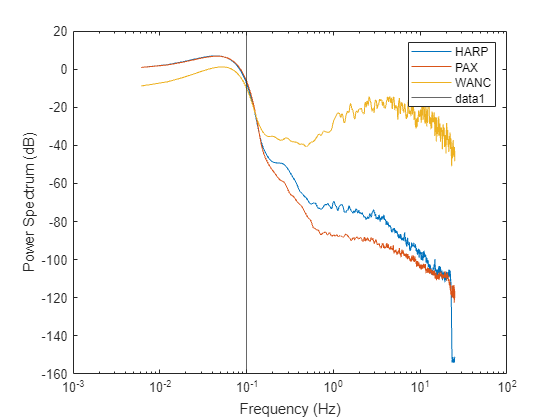

%Línea para banda de paso
xline(0.1)

Al filtrar la señal del monte Wrangell a 0,1 Hz, sólo se conservan las frecuencias situadas a la izquierda de la línea vertical. Puedes filtrar una tabla temporal con la función `lowpass:`

`lowpass(tbl,pass)`

Sólo necesitas filtrar la señal del Monte Wrangell, que se almacena en la variable `WANC` en la tabla `quakes`. Para filtrar una variable de una tabla temporal, se puede utilizar el operador dos puntos (`:`), que permite  obtener todas las muestras de una variable determinada.

`tbl(:, "NombreVariable")`

**ACTIVIDAD**

Realice un filtrado paso  bajo de la señal `WANC` almacenada en `quakes`, con una frecuencia de corte de 0,1 Hz. 

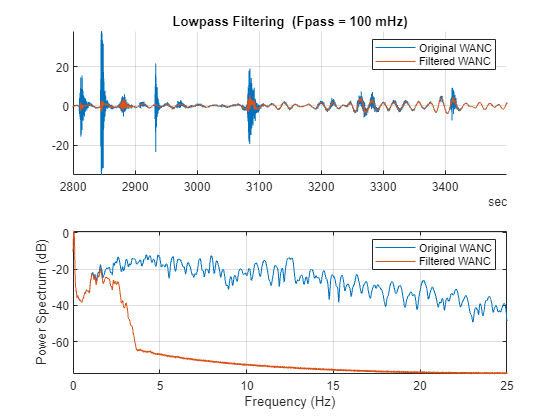

%Filtro paso bajo a Wanc, dejamos pasar frecuencias menores a 0.1 Hz
lowpass(quakes(:,"WANC"),0.1)

El gráfico muestra el dominio del tiempo y el dominio de la frecuencia para la señal del monte Wrangell. Observe que todavía hay frecuencias por encima de 0,1, pero el filtrado ha eliminado algunas de las frecuencias altas. A continuación, vamos a guardar la señal filtrada en una variable para poder compararla con las señales `HARP` y `PAX`.

**ACTIVIDAD**

Repite el comando de la tarea anterior, pero esta vez, utiliza una variable de salida llamada lowWANC donde se almacena la señal filtrada.

lowWANC = lowpass(quakes(:,"WANC"),0.1)

lowWANC = 35000×1 timetable
       Time         WANC  
    __________    ________

    2800 sec      -0.15802
    2800 sec      -0.19693
    2800 sec      -0.23722
    2800.1 sec    -0.27752
    2800.1 sec     -0.3164
    2800.1 sec    -0.35241
    2800.1 sec    -0.38422
    2800.1 sec    -0.41065
    2800.2 sec     -0.4308
    2800.2 sec    -0.44408
    2800.2 sec    -0.45025
    2800.2 sec    -0.44939
    2800.2 sec    -0.44194
    2800.3 sec    -0.42857
    2800.3 sec    -0.41018
    2800.3 sec    -0.38777


lowWANC es una tabla temporal con una variable llamada WANC. Como la dimension temporal de lowWANC sigue siendo la misma que la de `quakes`, puede añadir lowWANC como una nueva variable en la tabla temporal de `quakes`. Para añadir una nueva variable a una tabla, puede utilizar la notacion con punto.

`tbl.NewVar` `=` `data`

**ACTIVIDAD**

Añade `lowWANC.WANC` a la tabla `quakes`. Nombra la nueva variable como `FiltWANC`.

%Nueva tabla con la señal wanc filtrada
quakes.FiltWANC = lowWANC.WANC

quakes = 35000×4 timetable
       Time        HARP      PAX        WANC       FiltWANC
    __________    ______    ______    _________    ________

    2800 sec       2.203    2.2422     -0.14834    -0.15802
    2800 sec      2.2008    2.2448    -0.094129    -0.19693
    2800 sec      2.1986    2.2469     -0.11828    -0.23722
    2800.1 sec    2.1961    2.2489     -0.21078    -0.27752
    2800.1 sec    2.1938     2.251     -0.38239     -0.3164
    2800.1 sec    2.1915     2.253     -0.39148    -0.35241
    2800.1 sec    2.1893    2.2552      -0.4271    -0.38422
    2800.1 sec    2.1871    2.2573       -0.566    -0.41065
    2800.2 sec    2.1848    2.2594     -0.61011  

**ACTIVIDAD**

Crea una nueva figura utilizando el comando `figure`. Luego crea un gráfico apilado de todas las señales en `quakes`.

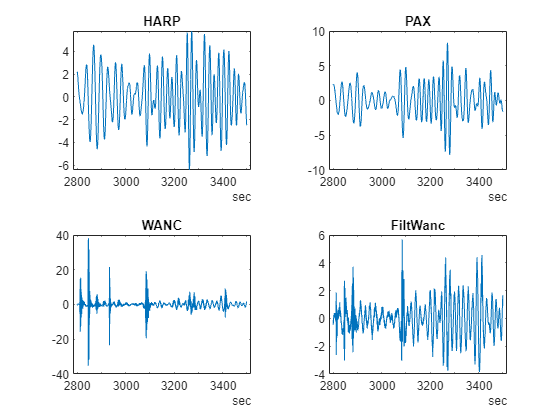

figure;
nexttile
plot(quakes.Time,quakes.HARP)
title("HARP");
nexttile
plot(quakes.Time,quakes.PAX)
title("PAX");
nexttile
plot(quakes.Time,quakes.WANC)
title("WANC");
nexttile
plot(quakes.Time,quakes.FiltWANC)
title("FiltWanc");

La grafica `FiltWANC` es similar al de `HARP` y `PAX`, pero muchas de las curvas son irregulares. Las curvas con pendientes pronunciadas contienen contenido de alta frecuencia residual que quedó despues del filtrado. Para reducir la cantidad de contenido de alta frecuencia en la señal filtrada, puede aumentar la pendiente en la banda de transicion del filtro. Esto se consigue aumentando la variable adimensional `Steepness`, la cual reduce la anchura de la banda de transicion. 

`sig = lowpass(tbl, pass, "Steepness",s)`

**ACTIVIDAD**

Actualice el código que realiza el filtrado paso bajo de la tarea anterior. Ajuste la opción "`Steepness`" a 0.95.

%Aumentamos pendiente de la banda de transición del filtro 
%Para quitar drásticamente altas frecuencias
lowWANC = lowpass(quakes(:,"WANC"),0.1,"Steepness",0.95);
quakes.FiltWANC = lowWANC.WANC

quakes = 35000×4 timetable
       Time        HARP      PAX        WANC       FiltWANC
    __________    ______    ______    _________    ________

    2800 sec       2.203    2.2422     -0.14834    -0.18483
    2800 sec      2.2008    2.2448    -0.094129    -0.19491
    2800 sec      2.1986    2.2469     -0.11828    -0.20462
    2800.1 sec    2.1961    2.2489     -0.21078    -0.21388
    2800.1 sec    2.1938     2.251     -0.38239    -0.22264
    2800.1 sec    2.1915     2.253     -0.39148    -0.23085
    2800.1 sec    2.1893    2.2552      -0.4271    -0.23846
    2800.1 sec    2.1871    2.2573       -0.566    -0.24544
    2800.2 sec    2.1848    2.2594     -0.61011  

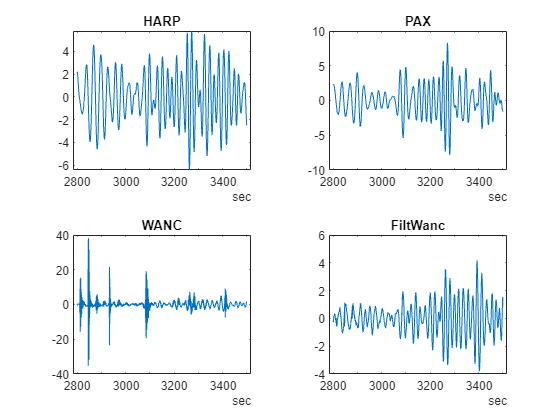

%Graficamos
figure
nexttile
plot(quakes.Time,quakes.HARP)
title("HARP");
nexttile
plot(quakes.Time,quakes.PAX)
title("PAX");
nexttile
plot(quakes.Time,quakes.WANC)
title("WANC");
nexttile
plot(quakes.Time,quakes.FiltWANC)
title("FiltWanc");

Las curvas de FiltWANC no son tan suaves como las de HARP y PAX, pero ahora es mas fácil comparar las 3 señales en el dominio del tiempo. De hecho, se puede apreciar cierto alineamiento entre maximos de la señal. Es decir, las componentes de alta frecuencia, provenientes de otras actividades sismicas cercanas, estaban impidiendo la visualizacion de las similitudes entre las señales. Para ver el efecto del `"Steepness"` al filtrar, pruebe a modificar el parametro y volver a ejecutar el script. 

## Filtrado paso banda

En la actividad anterior hemos extraído las bajas frecuencias, que correspondían a las ondas superficiales del terremoto de Sumatra. Ahora vamos a obtener el contenido de alta frecuencia, que corresponde a los terremotos locales cerca del Monte Wrangell. El rango de frecuencias de los terremotos locales es de 2 Hz a 10 Hz. Para extraer estas frecuencias, podemos utilizar un filtro paso banda para quedarte sólo con las frecuencias de ese rango.

`bandpass(tbl,[f1 f2])`

**ACTIVIDAD**

Filtre con un filtro paso banda la variable WANC en el intervalo de 2 a 10 Hz.

%Nos quedamos sólo con frecuencias de terremotos locales 
%Terremoto de Sumatra es de 0.05 Hz
bandWANC = bandpass(quakes(:,"WANC"),[2 10])

bandWANC = 35000×1 timetable
       Time         WANC   
    __________    _________

    2800 sec        0.09423
    2800 sec       0.096892
    2800 sec       0.089904
    2800.1 sec     0.063621
    2800.1 sec     0.016185
    2800.1 sec     -0.04228
    2800.1 sec    -0.094415
    2800.1 sec     -0.12542
    2800.2 sec     -0.13098
    2800.2 sec     -0.11789
    2800.2 sec    -0.096588
    2800.2 sec    -0.071275
    2800.2 sec    -0.036765
    2800.3 sec     0.012831
    2800.3 sec     0.070634
    2800.3 sec      0.11412


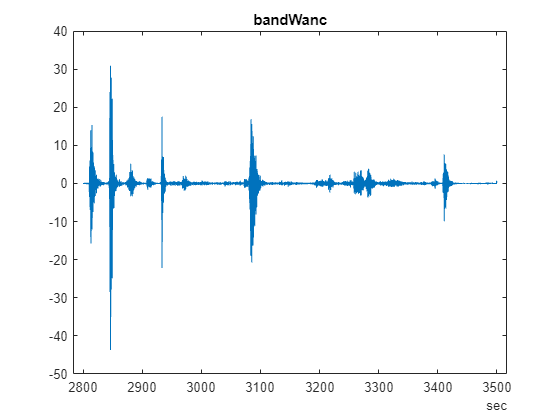

figure
plot(bandWANC.Time,bandWANC.WANC)
title("bandWanc");

Para represetar la señal filtrada con el filtro paso bajo y paso banda puedes combinarlas en una misma tabla de tiempos, con la sintaxis:

`tbl = timetable(t,sig1,sig2,'VariableNames',["A" "B"])`

**ACTIVIDAD**

En esta atcitividad queremos comparar la señal filtrada con las frecuencias bajas, que da cuenta de los eventos sismicos lejanos, con la version de frecuencias altas, que da cuenta de los eventos sismicos proximos. Para ello, cree una nueva tabla de tiempos llamada `compfilt` con las siguientes variables y nombres:

- El vector de tiempo de la tabla `quakes` o `bandWANC`

- Las señales bandWANC.WANC y `quakes`.FiltWANC

- Configure los nombres de las variables como "`Bandpass`" y "`Lowpass`".

%Comparamos señal de frecuencias bajas (Sumatra) y altas (locales)
compfilt = timetable(quakes.Time,bandWANC.WANC,quakes.FiltWANC,'VariableNames',["Bandpass" "Lowpass"])

compfilt = 35000×2 timetable
       Time       Bandpass     Lowpass 
    __________    _________    ________

    2800 sec        0.09423    -0.18483
    2800 sec       0.096892    -0.19491
    2800 sec       0.089904    -0.20462
    2800.1 sec     0.063621    -0.21388
    2800.1 sec     0.016185    -0.22264
    2800.1 sec     -0.04228    -0.23085
    2800.1 sec    -0.094415    -0.23846
    2800.1 sec     -0.12542    -0.24544
    2800.2 sec     -0.13098    -0.25176
    2800.2 sec     -0.11789    -0.25738
    2800.2 sec    -0.096588     -0.2623
    2800.2 sec    -0.071275     -0.2665
    2800.2 sec    -0.036765    -0.26997
    2800.3 sec     0.012831   

**ACTIVIDAD**

Cree una nueva figura introduciendo el comando `figure`, a continuacion, cree una pila de graficas de la tabla `compfilt`. Establezca los límites de la variable temporal de 2900 segundos a 2950 segundos para hacer zoom en dos de los terremotos locales.

%Recortamos tiempo y graficamos
roi = timerange(seconds(2900),seconds(2950));
compfilt = compfilt(roi,:)

compfilt = 2500×2 timetable
       Time        Bandpass     Lowpass 
    __________    __________    ________

    2900 sec       -0.053936    -0.58408
    2900 sec      -0.0065963    -0.58713
    2900 sec        0.067896    -0.59006
    2900.1 sec       0.14469    -0.59283
    2900.1 sec        0.1963    -0.59546
    2900.1 sec       0.20553    -0.59797
    2900.1 sec       0.17018    -0.60034
    2900.1 sec       0.10076    -0.60259
    2900.2 sec      0.014998    -0.60475
    2900.2 sec     -0.068321    -0.60683
    2900.2 sec      -0.13478    -0.60885
    2900.2 sec      -0.17722    -0.61084
    2900.2 sec      -0.19442     -0.6128
    2900.3 sec  

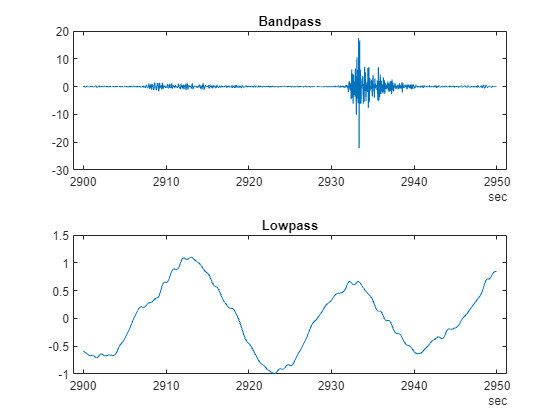

figure
nexttile
plot(compfilt.Time,compfilt.Bandpass);
title("Bandpass");
nexttile
plot(compfilt.Time,compfilt.Lowpass);
title("Lowpass");

La coincidencia temporal entre los terremotos primarios de Sumatra y los terremotos cercanos al Monte Wrangell confirma la idea de que el terremoto de Sumatra desencadenó una serie de terremotos de baja intensidad en Alaska, tal y como sospechaban los geologos. Gracias al filtrado, pudieron comparar las señales de baja y alta frecuencia del sismógrafo del monte Wrangell y separar los dos fenomenos. Esto les dio un argumento para confirmar la relación entre dos terremotos muy distantes. Si se desplaza por el gráfico, puede ver que cada pulso de alta frecuencia se produce cerca de un maximo en las ondas de baja frecuencia. También puede comparar las señales en el Analizador de señales, para ello descomente la siguiente linea de codigo:

signalAnalyzer(compfilt)

Pruebe a filtrar la señal del Monte Wrangell en el Analizador de Señal, en lugar de hacerlo con las funciones paso-bajo o paso-banda.

# Medida de señales

Como hemos visto, el terremoto de Sumatra fue tan potente que desencadenó terremotos más pequeños en lugares lejanos, como por ejemplo en Alaska. Para identificar estos terremotos individuales en los datos, necesitamos extraer alguna información de las señales. Extraer medidas de las señales es habitual en las aplicaciones de aprendizaje automático, en las que es necesario calcular características, o patrones de comportamiento que estan implicitos en los datos. A continuacion se muestra el espectrograma de la señal del Monte Wrangell en el rango de frecuencias entre 2Hz y 10Hz. 

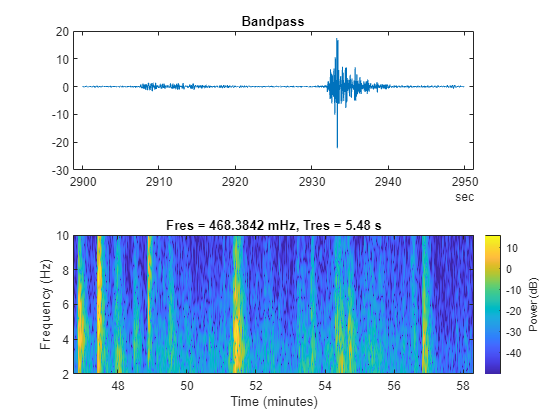

% This code loads the earthquake data.
load quakes
% This code creates the spectrogram from the Spectral Analysis chapter.
pspectrum(quakes.WANC,quakes.Time,"spectrogram","FrequencyLimits",[2 10],"MinThreshold",-50);

Sabemos que los terremotos cercanos producen oscilaciones en una banda de frecuencias de 2 Hz a 10 Hz. ¿Puedes utilizar este espectrograma para encontrar el momento exacto en que se produjeron los terremotos? Para calcular algun parametro a partir del espectrograma, primero necesitas obtener los datos del espectrograma (en lugar de la imagen), para ello llamamos a la funcion con vectores de salida:

`[``p``,``f``,``t``]` `=` `pspectrum``(``sig``,``time``,``"spectrogram"``)`

Las tres salidas son las densidades espectrales de potencia para cada segmento (ventana), las frecuencias y los instantes de tiempo correspondientes a cada segmento.

**ACTIVIDAD**

Copie el código utilizado para crear el espectrograma añadiendo tres argumentos de salida llamados `p`, `f` y` t.`

%Espectro, frecuencias y tiempos del espectrograma
[p,f,t] = pspectrum(quakes.WANC,quakes.Time,"spectrogram","FrequencyLimits",[2 10],"MinThreshold",-50);

Para saber qué intervalos de tiempo contienen la mayor parte de la potencia es necesario sumar la potencia del intervalo de frecuencias para cada segmento temporal, que son las diferentes columnas de `p`.

**ACTIVIDAD**

Calcule la suma (`sum`) de la matriz `p` y nombre la salida como `psum`. La funcion `sum`, por defecto calcula la suma por columnas. A continuación, cree un gráfico de `psum` frente a `t`.

%Suma por columnas -> Suma de las potencias para cada tiempo 
psum = sum(p)

psum = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0367    0.2039    0.1813    0.2241    0.0628    0.0451    0.0376    0.0178    0.0062    0.0041    0.0020    0.0009    0.0009    0.0002    0.0008    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.1176    1.5242    0.9006    0.5669    0.2204    0.0344    0.0224    0.0059    0.0037    0.0030    0.0007    0.0008    0.0004    0.0010    0.0006    0.0002    0.0001    0.0002    0.0001


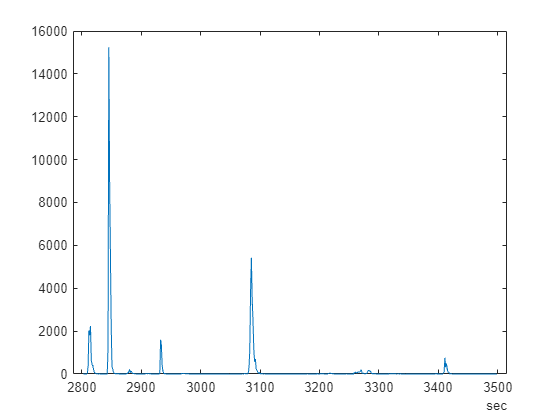

figure
plot(t,psum);

Puedes ver algunos picos en `psum`, pero algunos picos son mucho menos prominentes que otros. Para acentuar los picos puedes calcular la potencia en decibelios con la funcion:

`db``(``p``,``"power"``)`

**ACTIVIDAD**

Calcule la potencia de `psum` y llámala `pwr`. A continuación, cree un gráfico de `pwr` frente a `t`.

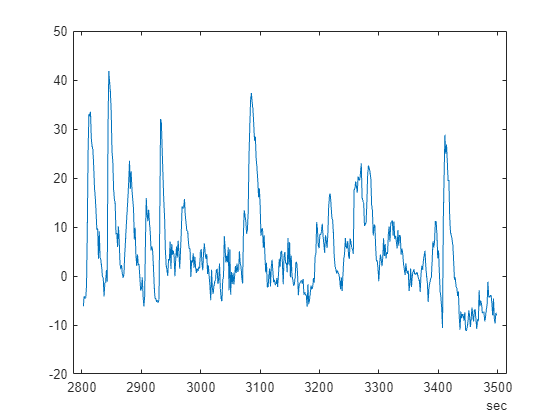

%Acentuamos los picos con decibelios
pwr = db(psum,"power");
plot(t,pwr);

Para localizar temporalmente cada terremoto, puedes encontrar la ubicación de estos picos. Puedes utilizar la herramienta interactiva "Find Local Extrema" para identificar a

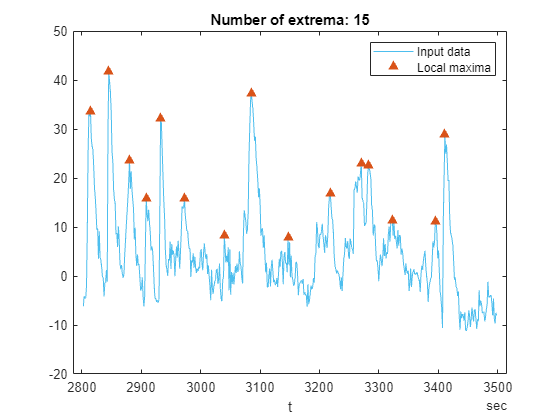

% Find local maxima
findquakes = islocalmax(pwr,"MinProminence",10,"ProminenceWindow",days(10),...
    "SamplePoints",t);

% Display results
figure
plot(t,pwr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(t(findquakes),pwr(findquakes),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(findquakes))
hold off
legend
xlabel("t")

utomáticamente mínimos o máximos locales en una señal.

**ACTIVIDAD**

- En la seccion Apps, añada la herramienta  interactiva "Find Local Extrema"  a la sección de código proporcionada para esta tarea

- Seleccione `pwr` como dato de entrada

- Nombre la variable de salida `findquakes`

- Seleccione `t` como dato del eje `x`

Las opciones por defecto encuentran demasiados extremos locales que pueden incluir ruido presente en la señal. Puede modificar las opciones para encontrar sólo los terremotos mas aislados. Si ya sabe cuántos terremotos encontrar, puede introducir ese valor para el número máximo de extremos. En la mayoría de los casos, no sabrá el número de extremos, por lo que puede modificar las opciones de prominencia y separación. La prominencia de un pico es una medida de su altura en relación con otros picos y la separacion define la posicion de un pico en relacion con los otros.

**ACTIVIDAD**

Aumente la opción de prominencia mínima a 10.

Puede visualizar los terremotos locales que acaba de identificar mediante la señal filtrada ejecutando el siguiente codigo. 

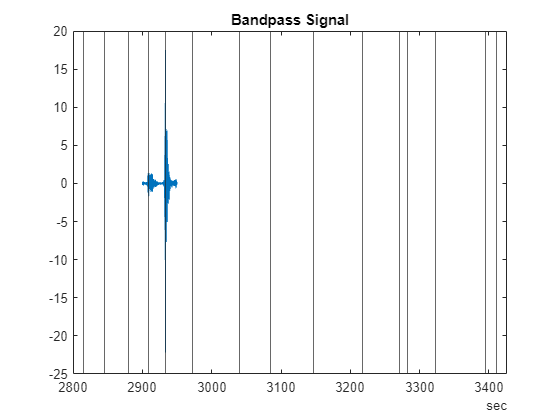

plot(compfilt.Time,compfilt.Bandpass)
xline(t(findquakes))
title("Bandpass Signal")